clear all;
close all;
clc;

% Animal = {'tph574'}; %'tph199';'tph209'
% Date = {'20250513'}; %'20240414'; % '20230602';'20230827'
% session_type = ''; %'StimProb' or 'Value'
% use_neural_time = true; % true: behavior_neural_timeを使用, false: behavior_raw_fpsを使用
% totalTrial = 200; %150;
% Key = {''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% % cellset_num = {-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% % categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% % layer_bounds_um = {[200,240,340,440,440]}; %{[240,280,340,380,380]}; %{[200,240,340,440,440]}; % %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% % Kota_alignment = 0; %0: do not use, 1:use
% % GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% % inside_trial_eta = 1; % 0:all time or 1: only during trial force & position eta 
% % Define the folder where the CSV files are located
% % pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% % image_reverse = {4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\'];

% Animal = {'tph574','tph574','tph574','tph574','tph578','tph578','tph578','tph578'}; %'tph199';'tph209'
% Date = {'20250514','20250516','20250518','20250520','20250514','20250516','20250518','20250520'}; %'20240414'; % '20230602';'20230827'
% % Animal = {'tph574','tph574','tph574','tph574','tph574','tph574','tph574','tph574','tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578'}; %'tph199';'tph209'
% % Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520'}; %'20240414'; % '20230602';'20230827'
% session_type = 'StimProb'; %'StimProb' or 'Value'
% use_neural_time = true; % true: behavior_neural_timeを使用, false: behavior_raw_fpsを使用
% totalTrial = 200; %150;
% Key = {'','','','','','','',''}; %,'','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% % cellset_num = {-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% % categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% % layer_bounds_um = {[200,240,340,440,440]}; %{[240,280,340,380,380]}; %{[200,240,340,440,440]}; % %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
% %     Inscopix imaging FOV % tph199:[247; 433; 358] 
% % Kota_alignment = 0; %0: do not use, 1:use
% % GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% % inside_trial_eta = 1; % 0:all time or 1: only during trial force & position eta 
% % Define the folder where the CSV files are located
% % pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% % need to be fixed because reverse pattern is different between tph189 and tph199 
% % image_reverse = {4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
% working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
% data_parent_dir = 'E:\Nao_behavior\202506';
% output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\'];

Animal = {'C6J501','C6J501','C6J501','C6J501','C6J501','C6J501'}; %'tph199';'tph209'
Date = {'20250704','20250708','20250710','20250711','20250715','20250717'}; %'20240414'; % '20230602';'20230827'
% Animal = {'tph574','tph574','tph574','tph574','tph574','tph574','tph574','tph574','tph578','tph578','tph578','tph578','tph578','tph578','tph578','tph578'}; %'tph199';'tph209'
% Date = {'20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520','20250513','20250514','20250515','20250516','20250517','20250518','20250519','20250520'}; %'20240414'; % '20230602';'20230827'
session_type = 'StimProb'; %'StimProb' or 'Value'
use_neural_time = true; % true: behavior_neural_timeを使用, false: behavior_raw_fpsを使用
totalTrial = 200; %150;
Key = {'','','','','',''};%,'','','','','','','','','',''}; %'switching'; %'roving'; %'heavy90';'roving25s'
% cellset_num = {-1}; %5; % num of session in all sessions % start from 0 -1: if cellset not used
% categorize = 'layer'; % categorize neurons by 'layer' or 'depth'
% layer_bounds_um = {[200,240,340,440,440]}; %{[240,280,340,380,380]}; %{[200,240,340,440,440]}; % %[0,0,0]; %[363, 498, 399]; %[431, 529]; %[191, 249, 303, 380, 412, 434]; %[297, 360, 332, 245, 430, 343]; %[168,373,418,437,451]; %[247; 433; 358] %[263; 492; 582]; %[left, center,right] of the
%     Inscopix imaging FOV % tph199:[247; 433; 358] 
% Kota_alignment = 0; %0: do not use, 1:use
% GC = 0; %1; % 0:not do, 1:do, Granger Causality Analysis
% inside_trial_eta = 1; % 0:all time or 1: only during trial force & position eta 
% Define the folder where the CSV files are located
% pullAlignFolderPath = 'E:\Nao_behavior\202504\20250416_tph578_roving\pull\output';
% need to be fixed because reverse pattern is different between tph189 and tph199 
% image_reverse = {4}; %0: tph199 type orientation, 1: arc247 type orientation, tph314 type orientation, 2:2024 S1, 3: M1, 4:Yuzhe-san orientation
working_directory = 'C:\Users\Naohiro\Documents\MATLAB\Makino2022\';
data_parent_dir = 'E:\Nao_behavior\202506_Abo';
output_parent_dir = ['C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\']; %'tph199';'tph209'

% --- ハイパーパラメータ：感覚ノイズ ---
sigma_sensory_noise = 0.0; %0.02; 
beta_decision = 10^10;

% uniqueDateとuniqueAnimalを取得
uniqueDate = unique(Date);
uniqueAnimal = unique(Animal);
uniqueKey = unique(Key);

% Outputパスのフォルダ名を生成
folder_name = [strrep(strjoin(uniqueAnimal),' ','_')];
% folder_name = [strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_')];

% 新しいフォルダのパスを作成
output_dir = fullfile(output_parent_dir, folder_name);

% フォルダが存在しない場合は作成
if ~exist(output_dir, 'dir')
    mkdir(output_dir);
end

% パスの最後に'/'を追加
if ~endsWith(output_dir, '/')
    output_dir = [output_dir '/'];
end

% フォルダ作成およびパスを表示
disp(['フォルダが作成されました: ' output_dir]);

フォルダが作成されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501/


% save parameters

% ファイル名を生成
filename = [output_dir strrep(strjoin(uniqueAnimal),' ','_') '_parameter.json'];
% filename = [output_dir strrep(strjoin(uniqueDate),' ','_') '_'  strrep(strjoin(uniqueAnimal),' ','_') '_parameter.json'];

% パラメータを構造体としてまとめる
params.Animal = Animal;
params.Date = Date;
params.totalTrial = totalTrial;
params.Key = Key;
params.working_directory = working_directory;
params.output_dir = output_dir;
params.data_parent_dir = data_parent_dir;
params.sigma_sensory_noise = sigma_sensory_noise;
params.beta_decision = beta_decision;

% JSONファイルとして保存
jsonText = jsonencode(params);
fid = fopen(filename, 'w');
if fid == -1
    error('ファイルを開くことができませんでした。');
end
fwrite(fid, jsonText, 'char');
fclose(fid);

disp(['パラメータが保存されました: ' filename]);

パラメータが保存されました: C:\Users\Naohiro\Documents\ThesisProjectAnalysis\output\260105_Abo_S1\C6J501/C6J501_parameter.json



Processing Animal: C6J501


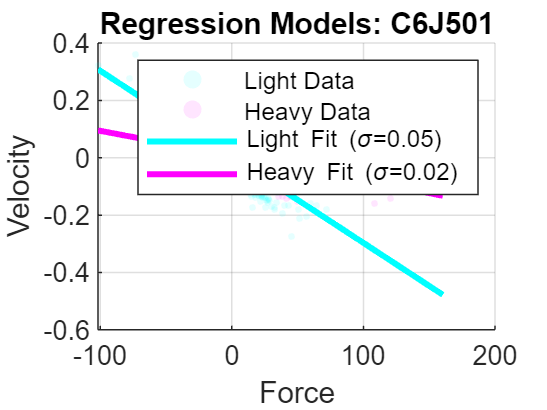

Animal C6J501 Accuracy: Model vs Truth = 89.50%, Model vs Choice = 84.00%
, Truth vs Choice = 74.67%


  Heavy 16: Model Acc = 66.7%, Behavior Acc = 53.3%
  Heavy 32: Model Acc = 98.0%, Behavior Acc = 82.5%
  Heavy 64: Model Acc = 100.0%, Behavior Acc = 84.6%


  Selection Bias (Pull %): Model = 63.0%, Behavior = 81.3%


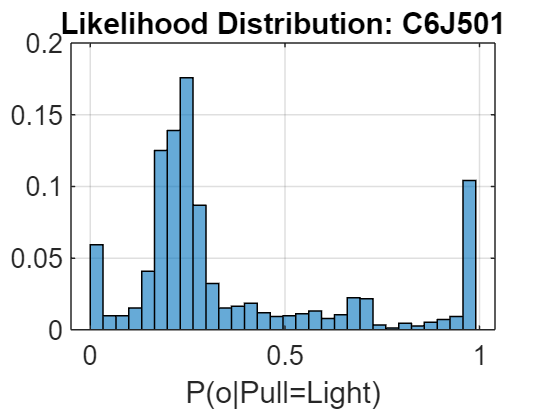

Saving bayesian_neural_time_clip for C6J501...


Saving convolved zscored data for C6J501...



Processing Animal: C6J501


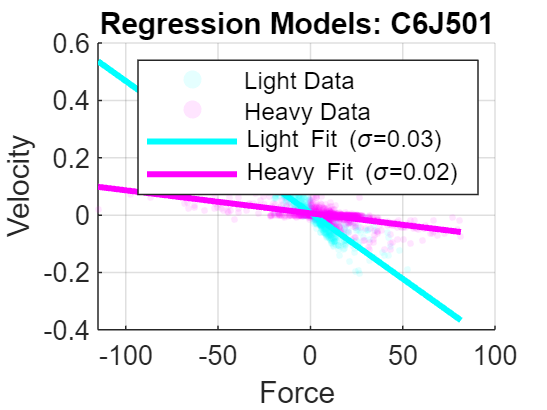

Animal C6J501 Accuracy: Model vs Truth = 92.50%, Model vs Choice = 88.81%
, Truth vs Choice = 83.22%


  Heavy 16: Model Acc = 71.7%, Behavior Acc = 71.8%
  Heavy 32: Model Acc = 100.0%, Behavior Acc = 87.5%
  Heavy 64: Model Acc = 100.0%, Behavior Acc = 87.5%


  Selection Bias (Pull %): Model = 51.0%, Behavior = 52.4%


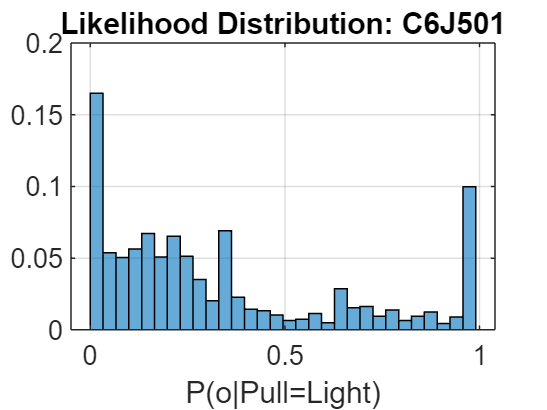

Saving bayesian_neural_time_clip for C6J501...


Saving convolved zscored data for C6J501...



Processing Animal: C6J501


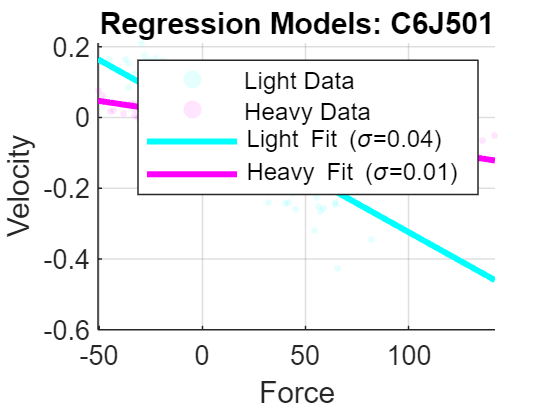

Animal C6J501 Accuracy: Model vs Truth = 89.00%, Model vs Choice = 77.62%
, Truth vs Choice = 74.83%


  Heavy 16: Model Acc = 66.7%, Behavior Acc = 64.0%
  Heavy 32: Model Acc = 86.8%, Behavior Acc = 75.0%
  Heavy 64: Model Acc = 97.3%, Behavior Acc = 78.0%


  Selection Bias (Pull %): Model = 62.0%, Behavior = 84.6%


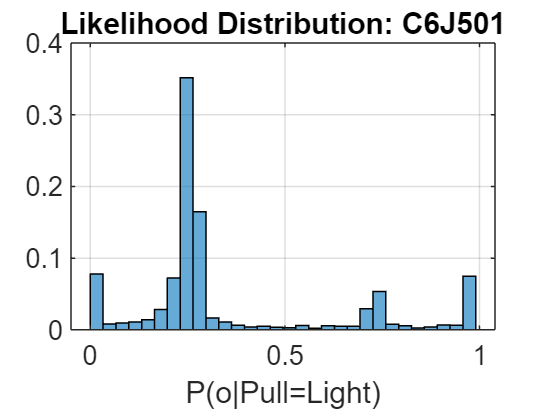

Saving bayesian_neural_time_clip for C6J501...


Saving convolved zscored data for C6J501...



Processing Animal: C6J501


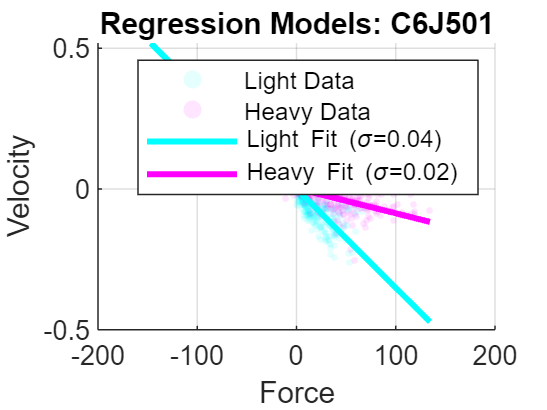

Animal C6J501 Accuracy: Model vs Truth = 89.00%, Model vs Choice = 72.39%
, Truth vs Choice = 67.16%


  Heavy 16: Model Acc = 70.4%, Behavior Acc = 68.4%
  Heavy 32: Model Acc = 93.3%, Behavior Acc = 57.7%
  Heavy 64: Model Acc = 97.0%, Behavior Acc = 70.0%


  Selection Bias (Pull %): Model = 49.5%, Behavior = 64.2%


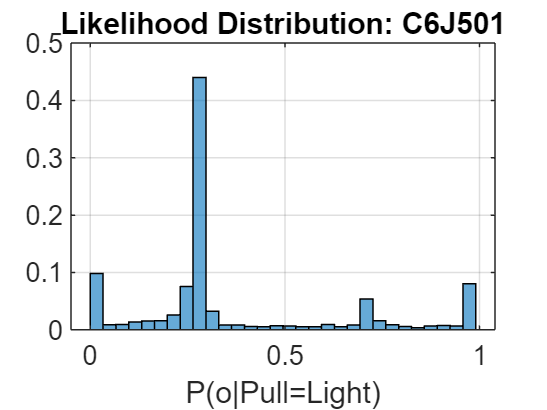

Saving bayesian_neural_time_clip for C6J501...


Saving convolved zscored data for C6J501...



Processing Animal: C6J501


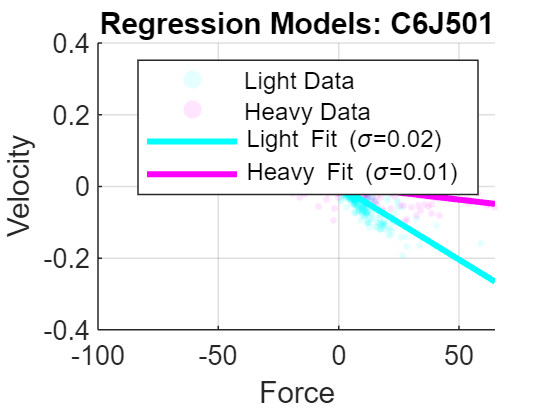

Animal C6J501 Accuracy: Model vs Truth = 91.00%, Model vs Choice = 89.13%
, Truth vs Choice = 85.51%


  Heavy 16: Model Acc = 75.0%, Behavior Acc = 68.4%
  Heavy 32: Model Acc = 93.9%, Behavior Acc = 87.9%
  Heavy 64: Model Acc = 98.9%, Behavior Acc = 94.0%


  Selection Bias (Pull %): Model = 45.5%, Behavior = 47.1%


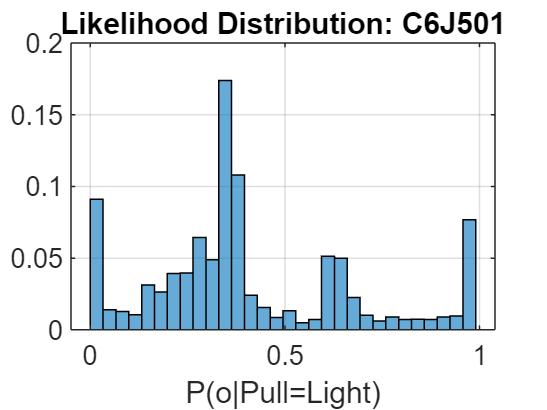

Saving bayesian_neural_time_clip for C6J501...


Saving convolved zscored data for C6J501...



Processing Animal: C6J501


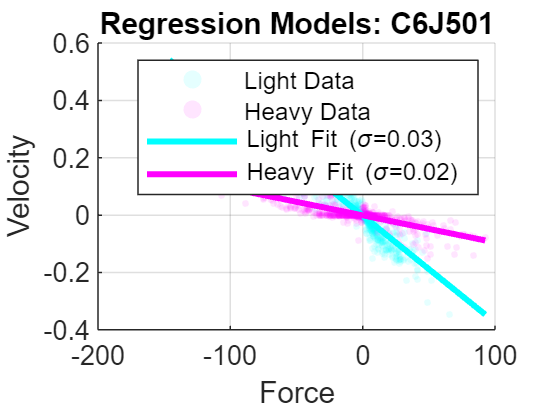

Animal C6J501 Accuracy: Model vs Truth = 89.50%, Model vs Choice = 88.24%
, Truth vs Choice = 80.15%


  Heavy 16: Model Acc = 61.2%, Behavior Acc = 62.9%
  Heavy 32: Model Acc = 100.0%, Behavior Acc = 75.0%
  Heavy 64: Model Acc = 98.0%, Behavior Acc = 91.3%


  Selection Bias (Pull %): Model = 48.0%, Behavior = 46.3%


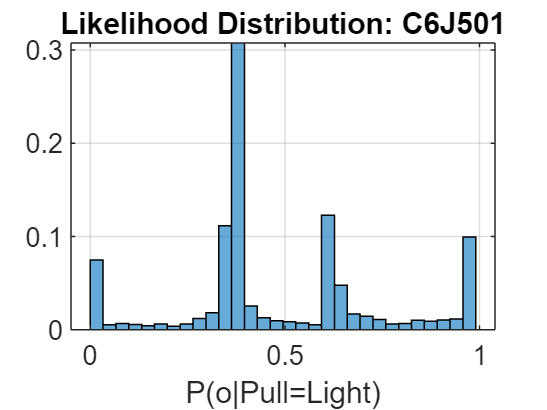

Saving bayesian_neural_time_clip for C6J501...


Saving convolved zscored data for C6J501...


% 全体集計用の変数を初期化
grand_map_array = [];
grand_correct_array = [];
grand_choice_array = [];
grand_heavy_val = []; % 全トライアルのHeavy抵抗値を保持

% 個体別のデータを格納する行列 [条件(6) x 動物数]
animal_pull_ratio_beh = nan(6, length(Animal));
animal_pull_ratio_mod = nan(6, length(Animal));
heavy_list_push = [64, 32, 16]; % 左側 (1:8, 1:4, 1:2) 用
heavy_list_pull = [16, 32, 64]; % 右側 (2:1, 4:1, 8:1) 用

for j_animal = 1:length(Animal)
    
    data_folder = [data_parent_dir filesep Date{j_animal} '_' Animal{j_animal} '_' Key{j_animal}];
    mat_filename = [data_folder filesep Animal{j_animal} '_behavior_' Date{j_animal} '_' Key{j_animal} '.mat'];
    
    fprintf('\nProcessing Animal: %s\n', Animal{j_animal});
    load(mat_filename);
    
    % 使用データの選択
    if use_neural_time
        raw_data = behavior_neural_time;
    else
        raw_data = behavior_raw_fps;
    end
    
    % 列インデックス (Preprocessの定義に準拠)
    COL_TIME = 1; COL_TRIAL = 2; COL_START = 3; COL_END = 4;
    COL_POS = 6; COL_FORCE = 7; COL_PUSH_RES = 10; COL_PULL_RES = 11;
    
    time_seq = raw_data(:, COL_TIME);
    trial_seq = raw_data(:, COL_TRIAL);
    pos_seq = raw_data(:, COL_POS);
    force_seq = raw_data(:, COL_FORCE);
    push_res_seq = raw_data(:, COL_PUSH_RES);
    pull_res_seq = raw_data(:, COL_PULL_RES);
    
    % 速度計算
    % dt_seq = [diff(time_seq); mean(diff(time_seq))];
    dt_seq_raw = diff(time_seq);
    dt_seq = [dt_seq_raw; mean(dt_seq_raw)]; 
    dt_seq(dt_seq == 0) = 1e-6;
    % vel_seq = [0; diff(pos_seq)] ./ dt_seq;
    vel_seq = [diff(pos_seq); 0] ./ dt_seq;
    
    % ---------------------------------------------------------
    % 1. 回帰分析とプロット
    % ---------------------------------------------------------
    num_steps = length(time_seq);
    train_mask = (trial_seq > 0) & (abs(force_seq) > 1e-3) & ~isnan(vel_seq);
    train_mask(num_steps) = false;
    f_tr = force_seq(train_mask); v_tr = vel_seq(train_mask);
    push_r_tr = push_res_seq(train_mask); pull_r_tr = pull_res_seq(train_mask);
    
    % Light/Heavy 分離
    idx_pull = f_tr > 0;
    f_light = [f_tr(idx_pull & pull_r_tr==8); f_tr(~idx_pull & push_r_tr==8)];
    v_light = [v_tr(idx_pull & pull_r_tr==8); v_tr(~idx_pull & push_r_tr==8)];
    f_heavy = [f_tr(idx_pull & pull_r_tr>8); f_tr(~idx_pull & push_r_tr>8)];
    v_heavy = [v_tr(idx_pull & pull_r_tr>8); v_tr(~idx_pull & push_r_tr>8)];
    
    % モデル推定 (NaN除去含む)
    [p_light, ~] = polyfit(f_light, v_light, 1);
    sigma_light = std(v_light - polyval(p_light, f_light), 'omitnan');
    [p_heavy, ~] = polyfit(f_heavy, v_heavy, 1);
    sigma_heavy = std(v_heavy - polyval(p_heavy, f_heavy), 'omitnan');
    
    % --- 回帰結果の確認プロット ---
    figure('Name', 'Regression Results'); hold on;
    scatter(f_light, v_light, 5, 'c', 'filled', 'MarkerFaceAlpha', 0.1, 'DisplayName', 'Light Data');
    scatter(f_heavy, v_heavy, 5, 'm', 'filled', 'MarkerFaceAlpha', 0.1, 'DisplayName', 'Heavy Data');
    f_range = linspace(min(f_tr), max(f_tr), 100);
    plot(f_range, polyval(p_light, f_range), 'c', 'LineWidth', 2, 'DisplayName', sprintf('Light Fit (\\sigma=%.2f)', sigma_light));
    plot(f_range, polyval(p_heavy, f_range), 'm', 'LineWidth', 2, 'DisplayName', sprintf('Heavy Fit (\\sigma=%.2f)', sigma_heavy));
    xlabel('Force'); ylabel('Velocity'); title(['Regression Models: ' Animal{j_animal}]);
    legend('show'); grid on;
    saveas(gcf, fullfile(output_dir, [Date{j_animal} '_' Animal{j_animal} '_regression_model.png']));

    % ---------------------------------------------------------
    % 2. 動的ベイズ推論
    % ---------------------------------------------------------
    num_steps = length(time_seq);
    % 格納用配列の初期化
    pull_obs_seq = zeros(num_steps, 1); % not used
    push_obs_seq = zeros(num_steps, 1); % note used
    pull_lik_seq = 0.5 * ones(num_steps, 1);
    push_lik_seq = 0.5 * ones(num_steps, 1);
    pull_post_seq = 0.5 * ones(num_steps, 1);
    push_post_seq = 0.5 * ones(num_steps, 1);
    pull_nll_seq = -log(0.5) * ones(num_steps, 1);
    push_nll_seq = -log(0.5) * ones(num_steps, 1);
    
    pull_prior = 0.5; push_prior = 0.5;
    
    for t = 1:num_steps-1
        curr_trial = trial_seq(t);
        % トライアル開始判定
        if (t==1 && curr_trial>0) || (t>1 && curr_trial>0 && curr_trial~=trial_seq(t-1))
            if strcmp(session_type, 'StimProb') && exist('pushCorrect','var')
                push_prob = pushCorrect(curr_trial);
                pull_prior = 1 - push_prob; push_prior = push_prob;
            else
                pull_prior = 0.5; push_prior = 0.5;
            end
            pull_post_seq(t) = pull_prior;
            push_post_seq(t) = push_prior;
        end
        
        if curr_trial > 0 && abs(force_seq(t)) > 1e-3
            % --- 感覚ノイズを考慮した分散の計算 ---
            sigma_L_total = sqrt(sigma_light^2 + sigma_sensory_noise^2);
            sigma_H_total = sqrt(sigma_heavy^2 + sigma_sensory_noise^2);

            % Likelihood
            lik_L = max(normpdf(vel_seq(t), p_light(1)*force_seq(t)+p_light(2), sigma_L_total), 1e-100);
            lik_H = max(normpdf(vel_seq(t), p_heavy(1)*force_seq(t)+p_heavy(2), sigma_H_total), 1e-100);
            norm_lik_L = max(min(lik_L / (lik_L + lik_H), 0.99), 0.01);
            
            % Context Mapping
            curr_pull_lik = norm_lik_L; if force_seq(t) < 0, curr_pull_lik = 1 - norm_lik_L; end
            curr_push_lik = 1 - curr_pull_lik;

            % Update
            pull_post = (curr_pull_lik * pull_prior) / (curr_pull_lik * pull_prior + (1-curr_pull_lik) * push_prior);
            pull_lik_seq(t+1) = curr_pull_lik; push_lik_seq(t+1) = curr_push_lik;
            pull_post_seq(t+1) = pull_post;   push_post_seq(t+1) = 1 - pull_post;
            % NLL
            pull_nll_seq(t+1) = -log(max(pull_lik_seq(t+1), 1e-10));
            push_nll_seq(t+1) = -log(max(push_lik_seq(t+1), 1e-10));             
            pull_prior = pull_post; push_prior = 1 - pull_post;
        else
            % Hold
            if t < num_steps
                pull_lik_seq(t+1) = 0.5;push_lik_seq(t+1) = 0.5;
                pull_nll_seq(t+1)  = -log(0.5);push_nll_seq(t+1)  = -log(0.5);
                pull_post_seq(t+1) = pull_post_seq(t);
                push_post_seq(t+1) = push_post_seq(t);
            end
            pull_prior = pull_post_seq(t+1); push_prior = 1 - pull_prior;
        end
      
    end

    % --- 新しい12列構成で作成 ---
    bayesian_neural_time = [time_seq, trial_seq, pull_res_seq, push_res_seq, ...
                            pull_obs_seq, push_obs_seq, ...
                            pull_lik_seq, push_lik_seq, ...
                            pull_post_seq, push_post_seq, ...
                            pull_nll_seq, push_nll_seq];    

    % ---------------------------------------------------------
    % 3. 個体ごとの精度表示とヒストグラム
    % ---------------------------------------------------------
    trial_ends = find(raw_data(:, COL_END) == 1);
    animal_map = []; animal_truth = []; animal_choice = [];
    animal_heavy_val = []; % トライアルごとのHeavy抵抗値(16,32,64)を格納
    
    pos_thresh_push = 687; pos_thresh_pull = 657; reward_window = 1000;

    for k = 1:length(trial_ends)
        idx = trial_ends(k); t_id = trial_seq(idx);
        % 1. 最終的な事後確率 P(Pull) を取得
        post_p = pull_post_seq(idx);
        
        % 2. 数値安定性のためのクリッピング (log(0)回避)
        post_p = max(min(post_p, 0.9999), 0.0001);
        
        % 3. ロジット (Log-odds) の計算
        %    確信度が高いほど、絶対値が大きくなります
        logit_p = log(post_p / (1 - post_p));
        
        % 4. Softmax関数による選択確率の計算
        %    beta倍することで、確信度に対する感度を調整します
        prob_choice_pull = 1 / (1 + exp(-beta_decision * logit_p));
        
        % 5. 乱数によるサンプリング (0 or 1)
        %    rand() が prob_choice_pull より小さければ Pull(1) を選択
        animal_map(k) = (rand() < prob_choice_pull);
        % 真の状態
        animal_truth(k) = (pull_res_seq(idx) < push_res_seq(idx));
        animal_heavy_val(k) = max(pull_res_seq(idx), push_res_seq(idx));
        % 動物の選択判定 (位置閾値)
        t_range = find(trial_seq == t_id);
        pos_trial = pos_seq(t_range);
        f_pull = find(pos_trial <= pos_thresh_pull, 1);
        f_push = find(pos_trial >= pos_thresh_push, 1);
        
        if isempty(f_pull) && isempty(f_push), animal_choice(k) = nan;
        elseif isempty(f_push) || (~isempty(f_pull) && f_pull < f_push), animal_choice(k) = 1; % Pull
        else, animal_choice(k) = 0; % Push
        end
    end
    
    % 精度表示
    acc_truth = mean(animal_map == animal_truth) * 100;
    valid_c = ~isnan(animal_choice);
    acc_choice = mean(animal_map(valid_c) == animal_choice(valid_c)) * 100;
    acc_animal_vs_truth = mean(animal_choice(valid_c) == animal_truth(valid_c)) * 100; 
    fprintf('Animal %s Accuracy: Model vs Truth = %.2f%%, Model vs Choice = %.2f%%\n, Truth vs Choice = %.2f%%\n', ...
        Animal{j_animal}, acc_truth, acc_choice, acc_animal_vs_truth);
    % 1. 抵抗値別の正解率 (16, 32, 64)
    heavy_levels = [16, 32, 64];
    for lv = heavy_levels
        idx_lv = (animal_heavy_val == lv);
        if any(idx_lv)
            acc_m_lv = mean(animal_map(idx_lv) == animal_truth(idx_lv)) * 100;
            acc_b_lv = mean(animal_choice(idx_lv & valid_c) == animal_truth(idx_lv & valid_c)) * 100;
            fprintf('  Heavy %d: Model Acc = %.1f%%, Behavior Acc = %.1f%%\n', lv, acc_m_lv, acc_b_lv);
        end
    end
    % --- 個体別のサイコメトリック・比率計算 (この個体の値を 1～6 の位置に格納) ---
    valid_c = ~isnan(animal_choice);
    % 左半分 (1:8, 1:4, 1:2) -> Truth=0 (Push正解) で Heavy=64, 32, 16
    for i = 1:3
        lv = heavy_list_push(i);
        idx_lv = (animal_heavy_val == lv) & (animal_truth == 0);
        
        if any(idx_lv), animal_pull_ratio_mod(i, j_animal) = mean(animal_map(idx_lv)); end
        if any(idx_lv & valid_c), animal_pull_ratio_beh(i, j_animal) = mean(animal_choice(idx_lv & valid_c)); end
    end
    
    % 右半分 (2:1, 4:1, 8:1) -> Truth=1 (Pull正解) で Heavy=16, 32, 64
    for i = 1:3
        lv = heavy_list_pull(i);
        idx_lv = (animal_heavy_val == lv) & (animal_truth == 1);
        
        % 格納先インデックスは 4, 5, 6
        if any(idx_lv), animal_pull_ratio_mod(i+3, j_animal) = mean(animal_map(idx_lv)); end
        if any(idx_lv & valid_c), animal_pull_ratio_beh(i+3, j_animal) = mean(animal_choice(idx_lv & valid_c)); end
    end  
    % 2. 選択バイアス (Pullを選択した割合)
    bias_model = mean(animal_map) * 100;
    bias_behavior = mean(animal_choice(valid_c)) * 100;
    fprintf('  Selection Bias (Pull %%): Model = %.1f%%, Behavior = %.1f%%\n', bias_model, bias_behavior);
    % 全体蓄積
    grand_map_array = [grand_map_array; animal_map'];
    grand_correct_array = [grand_correct_array; animal_truth'];
    grand_choice_array = [grand_choice_array; animal_choice'];
    grand_heavy_val = [grand_heavy_val; animal_heavy_val'];

    % --- 尤度ヒストグラム ---
    figure; histogram(pull_lik_seq(trial_seq > 0 & pull_lik_seq ~= 0.5), 30, 'Normalization', 'probability');
    title(['Likelihood Distribution: ' Animal{j_animal}]); xlabel('P(o|Pull=Light)'); grid on;
    saveas(gcf, fullfile(output_dir, [Animal{j_animal} '_Likelihood_Hist.png']));

    % 保存
    save(mat_filename, 'bayesian_neural_time', '-append');

    % =================================================================
    % --- 4. Bayesianデータのクリッピングと畳み込み (Encoding用) ---
    % =================================================================
    
    % --- 4.1 トライアル内データの抽出 (Clip) ---
    inside_trial_idx = (trial_seq ~= 0);
    bayesian_neural_time_clip = bayesian_neural_time(inside_trial_idx, :);
    
    % 保存
    fprintf('Saving bayesian_neural_time_clip for %s...\n', Animal{j_animal});
    save(mat_filename, 'bayesian_neural_time_clip', '-append');

    % --- 4.2 Raised Cosine フィルタによる畳み込み ---
    % フィルタ設計
    pull_posterior_filter = rcosdesign(0.25, 8, 4); 
    push_posterior_filter = rcosdesign(0.25, 8, 4);
    pull_nll_filter = rcosdesign(0.25, 8, 4);
    push_nll_filter = rcosdesign(0.25, 8, 4);
    
    % 変数の抽出 (bayesian_neural_timeの列定義に従う)
    % 9:PullPost, 10:PushPost, 11:PullNLL, 12:PushNLL
    pull_post_raw = bayesian_neural_time(:, 9);
    push_post_raw = bayesian_neural_time(:, 10);
    pull_nll_raw  = bayesian_neural_time(:, 11);
    push_nll_raw  = bayesian_neural_time(:, 12);
    
    % 畳み込み結果の格納用 (7つの時間窓)
    pull_post_conv = zeros(num_steps, 7);
    push_post_conv = zeros(num_steps, 7);
    pull_nll_conv  = zeros(num_steps, 7);
    push_nll_conv  = zeros(num_steps, 7);
    
    % 畳み込み実行
    c_pull_post = conv(pull_post_raw, pull_posterior_filter, 'full');
    c_push_post = conv(push_post_raw, push_posterior_filter, 'full');
    c_pull_nll  = conv(pull_nll_raw,  pull_nll_filter, 'full');
    c_push_nll  = conv(push_nll_raw,  push_nll_filter, 'full');
    
    % 末尾にバッファを追加 (スライド計算用)
    c_pull_post = [c_pull_post; zeros(8,1)];
    c_push_post = [c_push_post; zeros(8,1)];
    c_pull_nll  = [c_pull_nll;  zeros(8,1)];
    c_push_nll  = [c_push_nll;  zeros(8,1)];
    
    slide_width = 5; 
    for i = 1:7
        % 開始インデックスを計算
        start_idx = 17 + slide_width*(5-i);
        
        % 開始点から num_steps 個の要素を正確に抽出
        idx_range = start_idx : (start_idx + num_steps - 1);
        pull_post_conv(:,i) = c_pull_post(idx_range);
        push_post_conv(:,i) = c_push_post(idx_range);
        pull_nll_conv(:,i)  = c_pull_nll(idx_range);
        push_nll_conv(:,i)  = c_push_nll(idx_range);
    end
    
    % --- 4.3 Z-score 正規化 (全時間軸) ---
    bayesian_neural_time_convolved = [pull_post_conv, push_post_conv, pull_nll_conv, push_nll_conv];
    
    bn_mu = mean(bayesian_neural_time_convolved, 'omitnan');
    bn_sigma = std(bayesian_neural_time_convolved, 'omitnan');
    
    % 0除算防止のため最小値を1e-6に制限
    bayesian_neural_time_convolved_zscored = (bayesian_neural_time_convolved - bn_mu) ./ max(bn_sigma, 1e-6);
    
    % 保存
    save(mat_filename, 'bayesian_neural_time_convolved_zscored', '-append');
    
    % --- 4.4 Z-score 正規化 (トライアル内のみ抽出・再計算) ---
    bayesian_neural_time_convolved_clip = bayesian_neural_time_convolved(inside_trial_idx, :);
    
    bn_mu_clip = mean(bayesian_neural_time_convolved_clip, 'omitnan');
    bn_sigma_clip = std(bayesian_neural_time_convolved_clip, 'omitnan');
    
    bayesian_neural_time_convolved_zscored_clip = (bayesian_neural_time_convolved_clip - bn_mu_clip) ./ max(bn_sigma_clip, 1e-6);
    
    % 保存
    fprintf('Saving convolved zscored data for %s...\n', Animal{j_animal});
    save(mat_filename, 'bayesian_neural_time_convolved_zscored_clip', '-append');    

end


% --- 最終集計結果の表示 ---
fprintf('\n--- FINAL AGGREGATE RESULTS ---\n');


--- FINAL AGGREGATE RESULTS ---


fprintf('Global Model Accuracy (Model vs Truth): %.2f%%\n', mean(grand_map_array == grand_correct_array) * 100);

Global Model Accuracy (Model vs Truth): 90.08%


v_idx = ~isnan(grand_choice_array);
fprintf('Global Choice Accuracy (Model vs Behavior): %.2f%%\n', mean(grand_map_array(v_idx) == grand_choice_array(v_idx)) * 100);

Global Choice Accuracy (Model vs Behavior): 83.41%


fprintf('Global Choice Accuracy (Truth vs Behavior): %.2f%%\n', mean(grand_correct_array(v_idx) == grand_choice_array(v_idx)) * 100);

Global Choice Accuracy (Truth vs Behavior): 77.61%


% 2. 抵抗値レベル別の全体正解率
fprintf('\nAccuracy by Difficulty (Heavy Level):\n');


Accuracy by Difficulty (Heavy Level):


for lv = heavy_levels
    idx_lv = (grand_heavy_val == lv);
    if any(idx_lv)
        acc_m_lv = mean(grand_map_array(idx_lv) == grand_correct_array(idx_lv)) * 100;
        acc_b_lv = mean(grand_choice_array(idx_lv & v_idx) == grand_correct_array(idx_lv & v_idx)) * 100;
        fprintf('  Heavy %d: Model = %.1f%%, Behavior = %.1f%%\n', lv, acc_m_lv, acc_b_lv);
    end
end

  Heavy 16: Model = 68.8%, Behavior = 64.5%
  Heavy 32: Model = 95.2%, Behavior = 78.4%
  Heavy 64: Model = 98.5%, Behavior = 84.0%



% 3. 全体の選択バイアス
global_bias_m = mean(grand_map_array) * 100;
global_bias_b = mean(grand_choice_array(v_idx)) * 100;
fprintf('\nOverall Selection Bias (Pull Ratio):\n');


Overall Selection Bias (Pull Ratio):


fprintf('  Model Choice   : %.1f%% Pull\n', global_bias_m);

  Model Choice   : 53.2% Pull


fprintf('  Behavior Choice: %.1f%% Pull\n', global_bias_b);

  Behavior Choice: 63.0% Pull


fprintf('==================================================\n');

% % Calculate resistance posterior and prediction error based on Regression Likelihood
% % 回帰直線ベースの尤度計算とDBIの実装
% 
% data_raw = cell(length(Animal), totalTrial);
% data_folders = cell(length(Animal),1);
% grand_map_array = [];
% grand_correct_array = [];
% grand_choice_array = [];
% 
% for j_animal = 1:length(Animal)
%     data_folders(j_animal) = {[data_parent_dir filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
%     load([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_behavior_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat']);
%     data_raw(j_animal,:) = behavior_sequence_fps; %behavior_sequence; 
% 
%     % --- データ格納用変数の初期化 ---
%     obs_pull_cell = cell(1,200);
%     obs_push_cell = cell(1,200);
%     pull_correct_cell = cell(1,200);
%     force_cell = cell(1,200);
%     time_cell = cell(1,200);
%     position_cell = cell(1,200);    
%     velocity_cell = cell(1,200); % Velocity保存用に追加
% 
%     % --- 回帰分析用データプール ---
%     train_force_light = [];
%     train_vel_light = [];
%     train_force_heavy = [];
%     train_vel_heavy = [];
% 
%     % ---------------------------------------------------------
%     % 1. データ抽出と回帰分析用データの蓄積
%     % ---------------------------------------------------------
%     for i_trial = 1:size(data_raw, 2)
%         position_temp = data_raw{j_animal,i_trial}(:,3);
%         force_temp = data_raw{j_animal,i_trial}(:,4);
%         time_temp = data_raw{j_animal,i_trial}(:,6);
% 
%         % Velocityの計算
%         position_velocity = (position_temp(2:end)-position_temp(1:end-1)) ./ (time_temp(2:end)-time_temp(1:end-1));
% 
%         % データの保存
%         force_valid = force_temp(1:end-1);
%         obs_temp = position_velocity; % Velocityそのものを観測とする
% 
%         obs_pull = obs_temp .* (force_valid > 0);
%         obs_push = obs_temp .* (force_valid < 0);
% 
%         obs_pull_cell{i_trial} = [0; obs_pull];
%         obs_push_cell{i_trial} = [0; obs_push];
%         force_cell{i_trial} = force_temp;
%         velocity_cell{i_trial} = [0; position_velocity]; % 長さを合わせる
% 
%         pull_correct_cell{i_trial} = ones([size(obs_temp, 1) + 1, size(obs_temp, 2)]) * (pushResistance(i_trial) > pullResistance(i_trial));
%         time_cell{i_trial} = time_temp;
%         position_cell{i_trial} = position_temp;
% 
%         % --- 回帰分析用にデータを振り分け (修正版) ---
% 
%         % 1. ノイズ除去（Forceがほぼ0の点を除外）
%         valid_idx = abs(force_valid) > 1e-3; 
% 
%         f_clean = force_valid(valid_idx);
%         v_clean = position_velocity(valid_idx);
% 
%         % 2. 現在のトライアルの抵抗値設定を取得
%         pull_R = pullResistance(i_trial);
%         push_R = pushResistance(i_trial);
% 
%         % 3. データ点ごとに正負でマスクを作成
%         idx_pull = f_clean > 0; % Pull動作のデータ点
%         idx_push = f_clean < 0; % Push動作のデータ点
% 
%         % -----------------------------------------------------
%         % A. Pull動作 (Force > 0) のデータを割り当て
%         %    pullResistance を参照して Light(8) か Heavy(>8) か判定
%         % -----------------------------------------------------
%         if any(idx_pull)
%             if pull_R == 8
%                 train_force_light = [train_force_light; f_clean(idx_pull)];
%                 train_vel_light   = [train_vel_light;   v_clean(idx_pull)];
%             else
%                 % 8以外 (16, 32, 64) は Heavy へ
%                 train_force_heavy = [train_force_heavy; f_clean(idx_pull)];
%                 train_vel_heavy   = [train_vel_heavy;   v_clean(idx_pull)];
%             end
%         end
% 
%         % -----------------------------------------------------
%         % B. Push動作 (Force < 0) のデータを割り当て
%         %    pushResistance を参照して Light(8) か Heavy(>8) か判定
%         % -----------------------------------------------------
%         if any(idx_push)
%             if push_R == 8
%                 train_force_light = [train_force_light; f_clean(idx_push)];
%                 train_vel_light   = [train_vel_light;   v_clean(idx_push)];
%             else
%                 % 8以外 (16, 32, 64) は Heavy へ
%                 train_force_heavy = [train_force_heavy; f_clean(idx_push)];
%                 train_vel_heavy   = [train_vel_heavy;   v_clean(idx_push)];
%             end
%         end
%     end
% 
%     % ---------------------------------------------------------
%     % 2. 線形回帰によるパラメータ推定 (Training Phase)
%     %    Model: Velocity = S * Force + C + Noise
%     % ---------------------------------------------------------
% 
%     % --- データクレンジング (NaNと無限大を除去) ---
%     % Light Model用
%     valid_light = ~isnan(train_force_light) & ~isnan(train_vel_light) & isfinite(train_force_light) & isfinite(train_vel_light);
%     train_force_light = train_force_light(valid_light);
%     train_vel_light   = train_vel_light(valid_light);
% 
%     % Heavy Model用
%     valid_heavy = ~isnan(train_force_heavy) & ~isnan(train_vel_heavy) & isfinite(train_force_heavy) & isfinite(train_vel_heavy);
%     train_force_heavy = train_force_heavy(valid_heavy);
%     train_vel_heavy   = train_vel_heavy(valid_heavy);
% 
%     % --- Light Model (8 mN) の計算 ---
%     if length(train_force_light) > 1 && all(isfinite(train_force_light))
%         % fprintf('N points: %d\n', length(train_force_light));
%         % fprintf('Unique Force: %d\n', length(unique(train_force_light)));
%         % fprintf('Unique Velocity: %d\n', length(unique(train_vel_light)));        
%         [p_light, ~] = polyfit(train_force_light, train_vel_light, 1);
%         slope_light = p_light(1);
%         intercept_light = p_light(2);
% 
%         % 残差の計算
%         resid_light = train_vel_light - polyval(p_light, train_force_light);
%         sigma_light = std(resid_light, 'omitnan')
% 
%         % stdが0またはNaNになる場合の極小値処理
%         if isnan(sigma_light) || sigma_light == 0
%             sigma_light = 1e-3; 
%         end
%     else
%         % データが不足している場合のデフォルト値
%         warning('Light data insufficient for regression. Using default values.');
%         slope_light = 0; intercept_light = 0; sigma_light = 1; 
%     end
% 
% 
%     % --- Heavy Model (16-64 mN) の計算 ---
%     if length(train_force_heavy) > 1 && all(isfinite(train_force_heavy))
%         % fprintf('N points: %d\n', length(train_force_heavy));
%         % fprintf('Unique Force: %d\n', length(unique(train_force_heavy)));
%         % fprintf('Unique Velocity: %d\n', length(unique(train_vel_heavy)));        
%         [p_heavy, ~] = polyfit(train_force_heavy, train_vel_heavy, 1);
%         slope_heavy = p_heavy(1);
%         intercept_heavy = p_heavy(2);
% 
%         resid_heavy = train_vel_heavy - polyval(p_heavy, train_force_heavy);
%         sigma_heavy = std(resid_heavy, 'omitnan')
% 
%         if isnan(sigma_heavy) || sigma_heavy == 0
%             sigma_heavy = 1e-3;
%         end
%     else
%         warning('Heavy data insufficient for regression. Using default values.');
%         slope_heavy = 0; intercept_heavy = 0; sigma_heavy = 1;
%     end
% 
%     % --- 回帰結果の確認プロット ---
%     figure;
%     hold on;
%     scatter(train_force_light, train_vel_light, 5, 'c', 'filled', 'MarkerFaceAlpha', 0.1, 'DisplayName', 'Light Data');
%     scatter(train_force_heavy, train_vel_heavy, 5, 'm', 'filled', 'MarkerFaceAlpha', 0.1, 'DisplayName', 'Heavy Data');
% 
%     f_range = linspace(min(train_force_heavy), max(train_force_heavy), 100);
%     plot(f_range, polyval(p_light, f_range), 'c', 'LineWidth', 2, 'DisplayName', ['Light Fit (\sigma=' num2str(sigma_light, '%.2f') ')']);
%     plot(f_range, polyval(p_heavy, f_range), 'm', 'LineWidth', 2, 'DisplayName', ['Heavy Fit (\sigma=' num2str(sigma_heavy, '%.2f') ')']);
% 
%     title(['Regression Models for ' Animal{j_animal}]);
%     xlabel('Force'); ylabel('Velocity');
%     legend('show');
%     grid on;
%     filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_regression_model.png'];
%     saveas(gcf,filename);
% 
%     % ---------------------------------------------------------
%     % 3. 動的ベイズ推論 (Inference Phase)
%     % ---------------------------------------------------------
% 
%     pull_likelihood_cell = cell(1,200); 
%     push_likelihood_cell = cell(1,200);
%     pull_posterior_cell = cell(1,200);
%     push_posterior_cell = cell(1,200);    
%     pull_neg_log_likelihood_cell = cell(1,200); 
%     push_neg_log_likelihood_cell = cell(1,200);     
% 
%     for i_trial = 1:length(obs_pull_cell)
%         force_valid = force_cell{i_trial};
%         velocity_valid = velocity_cell{i_trial}; % Velocityを使用
% 
%         obs_len = length(velocity_valid);
% 
%         pull_likelihood_list = zeros(obs_len, 1);
%         push_likelihood_list = zeros(obs_len, 1);
%         pull_posterior_list = zeros(obs_len, 1);
%         push_posterior_list = zeros(obs_len, 1);
% 
%         % Initialize Priors for each trial
%         % StimProbセッションの場合は pushCorrect の値を使用してバイアスをかける
%         if strcmp(session_type, 'StimProb')
%             % pushCorrect(i_trial) が 0.8 や 0.2 などの事前確率を持っていると想定
%             push_prior = pushCorrect(i_trial); push_posterior_list(1) = pushCorrect(i_trial);
%             pull_prior = 1 - push_prior; pull_posterior_list(1) = 1 - push_prior; 
%         else
%             % それ以外のセッションは 0.5 (中立) から開始
%             pull_prior = 0.5; pull_posterior_list(1) = 0.5;
%             push_prior = 0.5; push_posterior_list(1) = 0.5;
%         end
% 
%         for n = 2:obs_len % n=1はデータがない(0埋め)ことが多いので2から
%             current_force = force_valid(n-1); % Force at t
%             current_vel = velocity_valid(n);  % Velocity at t+1 (observation)
% 
%             if abs(current_force) > 1e-3 % Forceが有意にある場合のみ更新
% 
%                 % --- Likelihood Calculation using Regression Models ---
% 
%                 % Hypothesis Light (8mN)
%                 pred_vel_light = slope_light * current_force + intercept_light;
%                 lik_light = normpdf(current_vel, pred_vel_light, sigma_light);
% 
%                 % Hypothesis Heavy (16-64mN)
%                 pred_vel_heavy = slope_heavy * current_force + intercept_heavy;
%                 lik_heavy = normpdf(current_vel, pred_vel_heavy, sigma_heavy);
% 
%                 % ゼロ除算防止
%                 lik_light = max(lik_light, 1e-100);
%                 lik_heavy = max(lik_heavy, 1e-100);
% 
%                 % Normalize Likelihoods (P(o|s))
%                 % ここではLightモデルとHeavyモデルの相対確率を計算
%                 sum_likelihood = lik_light + lik_heavy;
%                 norm_lik_light = lik_light / sum_likelihood;
%                 norm_lik_heavy = lik_heavy / sum_likelihood;
% 
%                 % 外れ値対策 (極端な確信度をクリップ)
%                 norm_lik_light = max(min(norm_lik_light, 0.99), 0.01);
% 
%                 % --- Context Mapping (Pull vs Push) ---
%                 % Pull Trial (Force > 0) -> Light means "Pull Correct" (if target is light) or context dependent.
%                 % ここでは元のコードのロジックに従い、Pull Likelihood = Light Likelihood として扱います。
%                 % ※ タスク定義に合わせて読み替えてください。
% 
%                 if current_force > 0 % Pull Action
%                     % Pull LikelihoodをLightモデルへの当てはまりとする
%                     current_pull_lik = norm_lik_light; 
%                     current_push_lik = 1 - current_pull_lik; % Heavy
%                 else % Push Action (Force < 0)
%                     % Push Actionの場合も、Lightモデルへの当てはまりを計算
%                     % もしPushがHeavyであることを検知したいなら逆になります
%                     current_push_lik = norm_lik_light; 
%                     current_pull_lik = 1 - current_push_lik;
%                 end
% 
%                 pull_likelihood_list(n) = current_pull_lik;
%                 push_likelihood_list(n) = current_push_lik;
% 
%                 % --- Posterior Update ---
%                 % Posterior = Likelihood * Prior
%                 pull_post_unnorm = current_pull_lik * pull_prior;
%                 push_post_unnorm = current_push_lik * push_prior;
% 
%                 marginal = pull_post_unnorm + push_post_unnorm;
% 
%                 pull_posterior = pull_post_unnorm / marginal;
%                 push_posterior = push_post_unnorm / marginal;
% 
%             else
%                 % Forceがない場合は更新しない (Priorを維持)
%                 pull_posterior = pull_prior;
%                 push_posterior = push_prior;
%                 pull_likelihood_list(n) = 0.5;
%                 push_likelihood_list(n) = 0.5;
%             end
% 
%             pull_posterior_list(n) = pull_posterior;
%             push_posterior_list(n) = push_posterior;
% 
%             % Update Prior for next step
%             pull_prior = min(max(pull_posterior, 0.01), 0.99);
%             push_prior = min(max(push_posterior, 0.01), 0.99);
%         end
% 
%         % --- Calculate Negative Log Likelihood ---
%         pull_neg_log_likelihood_list = -log(max(pull_likelihood_list, 1e-10));
%         push_neg_log_likelihood_list = -log(max(push_likelihood_list, 1e-10));
% 
%         % Store results
%         pull_likelihood_cell{i_trial} = pull_likelihood_list;
%         push_likelihood_cell{i_trial} = push_likelihood_list;
%         pull_posterior_cell{i_trial} = pull_posterior_list;
%         push_posterior_cell{i_trial} = push_posterior_list;
%         pull_neg_log_likelihood_cell{i_trial} = pull_neg_log_likelihood_list;
%         push_neg_log_likelihood_cell{i_trial} = push_neg_log_likelihood_list;
%     end
% 
%     % ---------------------------------------------------------
%     % 4. 結果のプロット (既存コードの流用・修正)
%     % ---------------------------------------------------------
%     pull_neg_log_likelihood_mat = cell2mat(pull_neg_log_likelihood_cell(:)); 
%     push_neg_log_likelihood_mat = cell2mat(push_neg_log_likelihood_cell(:));
%     pull_correct_mat = cell2mat(pull_correct_cell(:));
%     pull_posterior_mat = cell2mat(pull_posterior_cell(:));
% 
%     % データ結合
%     force_mat = cell2mat(force_cell(:));
%     position_mat = cell2mat(position_cell(:));
%     time_mat = cell2mat(time_cell(:));    
% 
%     % --- Visualization ---
%     figure;
%     hold on;
% 
%     % 時間軸の設定
%     if length(time_mat) > 4000
%         idx_start = 2000;
%         idx_end = 4000;
%         xlim_start = time_mat(idx_start);
%         xlim_end = time_mat(idx_end);
%         plot_idx = idx_start:idx_end;
%     else
%         plot_idx = 1:length(time_mat);
%         xlim_start = time_mat(1);
%         xlim_end = time_mat(end);
%     end
% 
%     % 左軸: Posterior
%     yyaxis left    
%     plot(time_mat(plot_idx), pull_posterior_mat(plot_idx), '-c', 'LineWidth', 1.5, 'DisplayName', 'Pull Posterior');
%     plot(time_mat(plot_idx), pull_correct_mat(plot_idx), '-m', 'LineWidth', 1.5, 'DisplayName', 'Truth (Pull Correct)');
%     ylabel('Posterior Probability');
%     ylim([-0.1, 1.1]);
%     ax = gca; ax.YColor = 'k';
% 
%     % 右軸: Kinematics
%     yyaxis right
%     % Z-score化して重ねて表示
%     pos_sub = position_mat(plot_idx);
%     force_sub = force_mat(plot_idx);
% 
%     plot(time_mat(plot_idx), (pos_sub - mean(pos_sub))/std(pos_sub), '-', 'Color', [0 0 0], 'LineWidth', 1.0, 'DisplayName', 'Position (z)');
%     plot(time_mat(plot_idx), (force_sub - mean(force_sub))/std(force_sub), '--', 'Color', [0.6 0.6 0.6], 'LineWidth', 1.0, 'DisplayName', 'Force (z)');
% 
%     ylabel('Kinematics (Z-scored)');
%     ax = gca; ax.YColor = 'k';
% 
%     xlabel('Time (ms)');
%     xlim([xlim_start, xlim_end]);
%     title(['DBI (Regression Model): ' Animal{j_animal}]);
%     legend('show', 'Location', 'northeastoutside');
%     grid on;
%     hold off;
% 
%     filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_Bayesian_Regression.png'];
%     saveas(gcf,filename);
% 
%     % --- 保存処理 ---
%     bayesian_sequence = cell(1, 200);
%     pull_correct_array = zeros(200,1);
%     map_array = zeros(200,1);
% 
%     % Choice判定用の配列をNaNで初期化 (例外データを除外するため)
%     pull_choice_array = nan(200, 1); 
% 
%     for i_trial = 1:200 
%         bayesian_sequence{i_trial} = [pull_correct_cell{i_trial} obs_pull_cell{i_trial} obs_push_cell{i_trial} ...
%                                       pull_likelihood_cell{i_trial} push_likelihood_cell{i_trial} ...
%                                       pull_posterior_cell{i_trial} push_posterior_cell{i_trial} ...
%                                       pull_neg_log_likelihood_cell{i_trial} push_neg_log_likelihood_cell{i_trial}];
% 
%         % 正解ラベルとMAP推定(Posterior)の取得
%         if ~isempty(pull_correct_cell{i_trial})
%             pull_correct_array(i_trial) = pull_correct_cell{i_trial}(end);
%             % モデルの判定: 1(Pull傾向) or 0(Push傾向)
%             map_array(i_trial) = (pull_posterior_cell{i_trial}(end) >= 0.5);
%         end
% 
%         % --- 動物の行動選択 (Choice) の判定 (マッピングをモデルと統合) ---
%         if ~isempty(position_cell{i_trial}) && ~isempty(time_cell{i_trial})
%             pos_diff = position_cell{i_trial}(end) - position_cell{i_trial}(1);
%             time_diff = time_cell{i_trial}(end) - time_cell{i_trial}(1);
% 
%             if time_diff <= 8000
%                 if pos_diff > 0
%                     pull_choice_array(i_trial) = 0; % 正の移動 -> 1 (Push) に修正
%                 elseif pos_diff < 0
%                     pull_choice_array(i_trial) = 1; % 負の移動 -> 0 (Pull) に修正
%                 end
%             end
%         end
%     end
% 
%     % --- 全体プールへデータを蓄積 ---
%     grand_map_array = [grand_map_array; map_array];
%     grand_correct_array = [grand_correct_array; pull_correct_array];
%     grand_choice_array = [grand_choice_array; pull_choice_array];
% 
%     % 個体ごとの精度を表示
%     accuracy = sum(map_array == pull_correct_array) / 200;
%     fprintf('Animal %s - Model Accuracy (vs Truth): %.2f%%\n', Animal{j_animal}, accuracy * 100); 
% 
%     valid_idx = ~isnan(pull_choice_array);
%     choice_accuracy = sum(map_array(valid_idx) == pull_choice_array(valid_idx)) / sum(valid_idx);
%     fprintf('Animal %s - Choice Accuracy (vs Behavior): %.2f%%\n', Animal{j_animal}, choice_accuracy * 100);    
% 
%     save([data_folders{j_animal} filesep Animal{j_animal} '_behavior_' Date{j_animal} '_' Key{j_animal} '.mat'], 'bayesian_sequence', '-append');
% 
%     % 1. モデルの正解率 (Task Truth vs Model Prediction)
%     accuracy = sum(map_array == pull_correct_array) / 200;
%     fprintf('Model Accuracy (vs Truth): %.2f%%\n', accuracy * 100); 
% 
%     % 2. モデル予測と実際の選択の一致率 (Choice Accuracy: Model Prediction vs Animal Choice)
%     % NaNとの比較 (1 == NaN) は 0 (False) になるため、例外トライアルはsumに含まれません
%     choice_accuracy = sum(map_array == pull_choice_array) / 200;
%     fprintf('Choice Accuracy (vs Animal Behavior): %.2f%%\n', choice_accuracy * 100);
% 
%     % --- 尤度ヒストグラム ---
%     all_pull_lik = cell2mat(pull_likelihood_cell(:));
%     valid_lik = all_pull_lik(all_pull_lik > 0.01 & all_pull_lik < 0.99); % 極端な値を除いて分布を見る
% 
%     figure;
%     histogram(valid_lik, 30, 'Normalization', 'probability');
%     title('Distribution of Intermediate Likelihoods');
%     xlabel('Likelihood P(o|Light)');
%     grid on;
% end
% 
% % --- 全個体を通じた最終的な精度算出 (すべてのループ終了後) ---
% fprintf('\n==================================================\n');
% fprintf('FINAL AGGREGATE RESULTS (All Animals)\n');
% fprintf('==================================================\n');
% 
% % 1. モデル全体の正解率 (予測 vs 正解)
% % $$ \text{Total Model Acc} = \frac{\sum (\text{MAP} == \text{Truth})}{N} $$
% total_model_acc = sum(grand_map_array == grand_correct_array) / length(grand_map_array);
% fprintf('Global Model Accuracy (vs Truth): %.2f%% (n=%d trials)\n', ...
%     total_model_acc * 100, length(grand_map_array));
% 
% % 2. モデル全体の行動一致率 (予測 vs 実際の選択)
% % 有効なトライアル (NaNでないもの) のみ抽出
% valid_total_idx = ~isnan(grand_choice_array);
% total_choice_acc = sum(grand_map_array(valid_total_idx) == grand_choice_array(valid_total_idx)) / sum(valid_total_idx);
% fprintf('Global Choice Accuracy (vs Behavior): %.2f%% (n=%d valid trials)\n', ...
%     total_choice_acc * 100, sum(valid_total_idx));
% fprintf('==================================================\n');

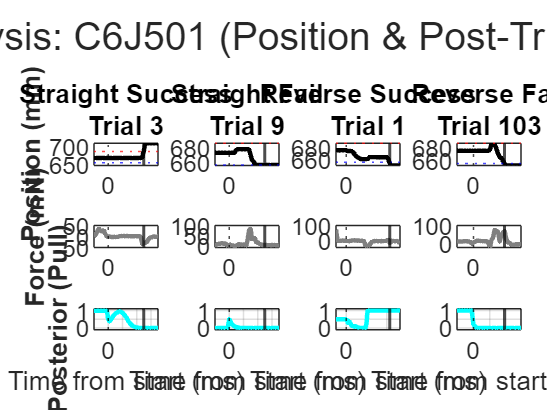

%% カテゴリ別の縦並びプロット (判定ロジック更新版)

% --- 定数の設定 ---
pos_thresh_push = 687; % レバー押し切りの閾値
pos_thresh_pull = 657; % レバー引き切りの閾値
F_threshold = 16;      % 初動判定用の力の閾値
reward_window_ms = 1000; % トライアル終了後、報酬をチェックする期間(ms)
buffer_pts = 10;       % プロット時の前後バッファ

% カテゴリ分類用のリストを初期化
idx_SS = []; idx_SF = []; idx_RS = []; idx_RF = [];

% 全トライアルIDを取得 (0はITI)
unique_trial_ids = unique(trial_seq(trial_seq > 0));

for i = 1:length(unique_trial_ids)
    t_id = unique_trial_ids(i);
    t_idx = find(trial_seq == t_id);
    if isempty(t_idx), continue; end
    
    % --- 1. レバー選択の判定 (位置ベース) ---
    % トライアル期間中の位置データを取得
    pos_trial = pos_seq(t_idx);
    
    % どちらの閾値に先に達したかを確認
    first_push_idx = find(pos_trial >= pos_thresh_push, 1);
    first_pull_idx = find(pos_trial <= pos_thresh_pull, 1);
    
    if isempty(first_push_idx) && isempty(first_pull_idx)
        continue; % どちらにも達していない（タイムアウト等）場合は除外
    end
    
    % 最終的な選択方向を決定 (1: Pull, 0: Push)
    if isempty(first_pull_idx)
        choice_side = 0; % Pushのみ達成
    elseif isempty(first_push_idx)
        choice_side = 1; % Pullのみ達成
    elseif first_pull_idx < first_push_idx
        choice_side = 1; % Pullに先に到達
    else
        choice_side = 0; % Pushに先に到達
    end

    % --- 2. 報酬（成功）の判定 (終了後1秒以内) ---
    end_time = time_seq(t_idx(end));
    % 終了時刻から1秒以内のインデックス範囲を特定
    post_trial_idx = find(time_seq > end_time & time_seq <= (end_time + reward_window_ms));
    
    if ~isempty(post_trial_idx) && any(raw_data(post_trial_idx, 8) == 1)
        is_success = 1;
    else
        is_success = 0;
    end

    % --- 3. 初動(Straight/Reverse)の判定 ---
    f_trial = force_seq(t_idx);
    fm_local = find(abs(f_trial) > F_threshold, 1);
    
    if isempty(fm_local), continue; end
    
    initial_side = (f_trial(fm_local) > 0); % 1: Pull(+), 0: Push(-)
    is_straight = (initial_side == choice_side);

    % --- 4. カテゴライズ ---
    if is_straight && is_success
        idx_SS = [idx_SS, t_id];
    elseif is_straight && ~is_success
        idx_SF = [idx_SF, t_id];
    elseif ~is_straight && is_success
        idx_RS = [idx_RS, t_id];
    elseif ~is_straight && ~is_success
        idx_RF = [idx_RF, t_id];
    end
end

% --- 5. プロット実行部分 (構造は前回と同様) ---
categories = {idx_SS, idx_SF, idx_RS, idx_RF};
cat_names = {'Straight Success', 'Straight Fail', 'Reverse Success', 'Reverse Fail'};
var_names = {'Position (mm)', 'Force (mN)', 'Posterior (Pull)'};
colors = {'k', [0.5 0.5 0.5], 'c'};

figure('Name', 'Behavioral Category Analysis', 'Position', [100, 50, 1200, 900]);
tlo = tiledlayout(3, 4, 'TileSpacing', 'compact', 'Padding', 'compact');

for c = 1:4
    target_ids = categories{c};
    if isempty(target_ids)
        for v = 1:3, nexttile((v-1)*4 + c); title([cat_names{c} ' (No Data)']); end
        continue;
    end
    
    % 代表1件を抽出
    t_id = target_ids(1);
    t_idx = find(trial_seq == t_id);
    plot_idx = max(1, t_idx(1)-buffer_pts) : min(length(trial_seq), t_idx(end)+buffer_pts);
    
    time_zeroed = time_seq(plot_idx) - time_seq(t_idx(1));
    data_to_plot = {pos_seq(plot_idx), force_seq(plot_idx), pull_post_seq(plot_idx)};
    
    for v = 1:3
        nexttile((v-1)*4 + c);
        plot(time_zeroed, data_to_plot{v}, 'Color', colors{v}, 'LineWidth', 1.5);
        hold on;
        
        % 閾値達成位置をマーク (Positionパネルの場合のみ水平線)
        if v == 1
            yline(pos_thresh_push, 'r:', 'HandleVisibility', 'off');
            yline(pos_thresh_pull, 'b:', 'HandleVisibility', 'off');
        end
        
        % 終了ラインと1秒後の報酬確認ウィンドウの終わりを明示
        xline(0, 'k:'); % Start
        xline(time_seq(t_idx(end)) - time_seq(t_idx(1)), 'k--', 'LineWidth', 1); % End
        
        if v == 1, title(sprintf('%s\nTrial %d', cat_names{c}, t_id)); end
        if c == 1, ylabel(var_names{v}, 'FontWeight', 'bold'); end
        if v == 3, xlabel('Time from start (ms)'); ylim([-0.1 1.1]); grid on; end
    end
end
sgtitle(['Category Analysis: ' Animal{j_animal} ' (Position & Post-Trial Reward Criteria)']);

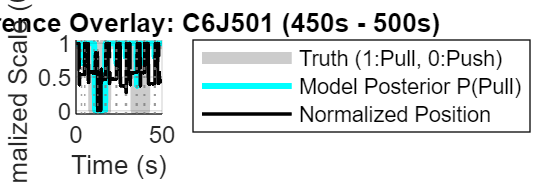

%% 5. 50秒間の時系列重ね合わせプロット (Truth, Posterior, Position)

% --- パラメータ設定 ---
plot_start_s = 450;  % プロット開始秒数 (任意に調整してください)
plot_duration_s = 50; % 切り出す長さ (秒)
fps_data = 10;        % データのサンプリングレート

% --- データの切り出し範囲計算 ---
% time_seq は ms 単位を想定
start_ms = plot_start_s * 1000;
end_ms = (plot_start_s + plot_duration_s) * 1000;
idx_range = find(time_seq >= start_ms & time_seq <= end_ms);

if isempty(idx_range)
    warning('指定された時間範囲にデータが存在しません。');
else
    % --- プロットデータの準備と正規化 ---
    t_plot = (time_seq(idx_range) - start_ms) / 1000; % 秒単位 (0s開始)
    
    % 1. 真の状態 (Truth): 1:Pullが正解, 0:Pushが正解
    % pull_res_seq < push_res_seq なら Pullが軽い(正解)
    truth_plot = double(pull_res_seq(idx_range) < push_res_seq(idx_range));
    % ITI(トライアル外)で抵抗値がInfの場合、見づらいため直前の値を維持させる処理
    truth_plot(pull_res_seq(idx_range) == inf) = NaN;
    truth_plot = fillmissing(truth_plot, 'previous');
    if isnan(truth_plot(1)), truth_plot = fillmissing(truth_plot, 'next'); end

    % 2. モデルの事後分布 (Posterior): 1:Pull側への確信
    post_plot = pull_post_seq(idx_range);

    % 3. レバー位置 (Position) の正規化: 657(Pull) -> 1, 687(Push) -> 0
    % (ユーザー指定の範囲 657-687 を 0-1 に変換。向きを他と合わせるため反転)
    pos_raw = pos_seq(idx_range);
    pos_norm = 1 - (pos_raw - 657) / (687 - 657); 
    % 範囲外をクリップ (プロットを綺麗にするため)
    pos_norm(pos_norm > 1) = 1; 
    pos_norm(pos_norm < 0) = 0;

    % --- プロット実行 ---
    figure('Name', 'Overlay Timecourse (50s)', 'Position', [100, 100, 1200, 400]);
    hold on;

    % 真の状態を背景的な太線で表示 (薄いグレー)
    plot(t_plot, truth_plot, 'Color', [0.8 0.8 0.8], 'LineWidth', 4, 'DisplayName', 'Truth (1:Pull, 0:Push)');
    
    % モデルの事後分布をプロット (シアン)
    plot(t_plot, post_plot, 'Color', 'c', 'LineWidth', 2, 'DisplayName', 'Model Posterior P(Pull)');
    
    % レバー位置をプロット (黒)
    plot(t_plot, pos_norm, 'Color', 'k', 'LineWidth', 1.2, 'DisplayName', 'Normalized Position');

    % トライアルの境界線を点線で描画 (trial_seqの変化点)
    trial_change = find(diff(trial_seq(idx_range)) ~= 0);
    for tc = 1:length(trial_change)
        xline(t_plot(trial_change(tc)), ':', 'Color', [0.5 0.5 0.5], 'HandleVisibility', 'off');
    end

    % --- 装飾 ---
    title(sprintf('Behavior & Inference Overlay: %s (%ds - %ds)', Animal{j_animal}, plot_start_s, plot_start_s + plot_duration_s));
    xlabel('Time (s)');
    ylabel('Normalized Scale (0 to 1)');
    ylim([-0.05 1.05]);
    legend('Location', 'northeastoutside');
    grid on;
    set(gca, 'Layer', 'top'); % グリッドを背面に

    % 保存
    saveas(gcf, fullfile(output_dir, [Animal{j_animal} '_overlay_50s.png']));
end

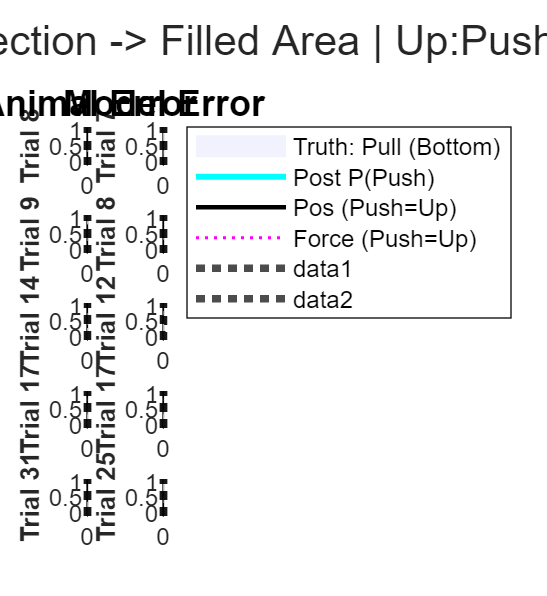

%% 6. 誤選択トライアルのダイナミクス解析 (反転プロット版)

% --- エラーデータの抽出 (前回と同様) ---
animal_error_ids = [];
model_error_ids = [];

for i = 1:length(unique_trial_ids)
    t_id = unique_trial_ids(i);
    t_idx = find(trial_seq == t_id);
    if isempty(t_idx), continue; end
    
    truth_side = double(pull_res_seq(t_idx(1)) < push_res_seq(t_idx(1))); % 1:Pull, 0:Push
    
    pos_trial = pos_seq(t_idx);
    f_pull = find(pos_trial <= pos_thresh_pull, 1);
    f_push = find(pos_trial >= pos_thresh_push, 1);
    if isempty(f_pull) && isempty(f_push), choice_side = nan;
    elseif isempty(f_push) || (~isempty(f_pull) && f_pull < f_push), choice_side = 1; % Pull
    else, choice_side = 0; % Push
    end
    
    model_side = double(pull_post_seq(t_idx(end)) >= 0.5); % 1:Pull, 0:Push
    
    if ~isnan(choice_side) && (choice_side ~= truth_side), animal_error_ids = [animal_error_ids, t_id]; end
    if model_side ~= truth_side, model_error_ids = [model_error_ids, t_id]; end
end

num_plot_ex = 5;
target_animal_err = animal_error_ids(1:min(end, num_plot_ex));
target_model_err = model_error_ids(1:min(end, num_plot_ex));

figure('Name', 'Inverted Error Dynamics Analysis', 'Position', [100, 100, 1100, 1200]);
tlo_err = tiledlayout(num_plot_ex, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for row = 1:num_plot_ex
    for col = 1:2
        if col == 1
            if row > length(target_animal_err), nexttile; axis off; continue; end
            curr_id = target_animal_err(row); title_prefix = 'Animal Error';
        else
            if row > length(target_model_err), nexttile; axis off; continue; end
            curr_id = target_model_err(row); title_prefix = 'Model Error';
        end
        
        t_idx = find(trial_seq == curr_id);
        plot_idx = max(1, t_idx(1)-buffer_pts) : min(length(trial_seq), t_idx(end)+buffer_pts);
        t_rel = (time_seq(plot_idx) - time_seq(t_idx(1))); 
        
        % --- 1. 真の状態 (Truth): 0=Push, 1=Pull ---
        truth = double(pull_res_seq(t_idx(1)) < push_res_seq(t_idx(1)));
        
        % --- 2. 各変数の正規化修正 ---
        % Posterior (Pullの確率): 0~1のまま (0:Push寄り, 1:Pull寄り)
        post = 1-pull_post_seq(plot_idx);
        
        % Position (値が大きい687[Push]を上[1]に、657[Pull]を下[0]に)
        pos_n = (pos_seq(plot_idx) - pos_thresh_pull) / (pos_thresh_push - pos_thresh_pull);
        pos_n(pos_n > 1) = 1.05; pos_n(pos_n < 0) = -0.05;
        
        % Force (正負反転: Push[-]をプラス方向、Pull[+]をマイナス方向に)
        % スケーリング: -200mN(Push) -> 1, +200mN(Pull) -> 0
        force_inv = -force_seq(plot_idx); 
        force_n = (force_inv + 100) / 200;
        force_n(force_n > 1) = 1; force_n(force_n < 0) = 0;

        nexttile; hold on;
        
        % --- 3. 背景の塗りつぶし (State) ---
        % Push(0)の場合: 上半分(0.5 ~ 1.1)を赤系で
        % Pull(1)の場合: 下半分(-0.1 ~ 0.5)を青系で
        if truth == 0 % Push
            patch([t_rel(1) t_rel(end) t_rel(end) t_rel(1)], [0.5 0.5 1.1 1.1], [1 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.5, 'DisplayName', 'Truth: Push (Top)');
        else % Pull
            patch([t_rel(1) t_rel(end) t_rel(end) t_rel(1)], [-0.1 -0.1 0.5 0.5], [0.9 0.9 1], 'EdgeColor', 'none', 'FaceAlpha', 0.5, 'DisplayName', 'Truth: Pull (Bottom)');
        end
        
        % --- 4. プロット実行 ---
        plot(t_rel, post, 'c', 'LineWidth', 2, 'DisplayName', 'Post P(Push)'); % シアン
        plot(t_rel, pos_n, 'k', 'LineWidth', 1.5, 'DisplayName', 'Pos (Push=Up)'); % 黒
        plot(t_rel, force_n, 'm:', 'LineWidth', 1, 'DisplayName', 'Force (Push=Up)'); % マゼンタ
        
        % --- 5. 補助線 (太い点線) ---
        yline(0.5, '--', 'Color', [0.5 0.5 0.5], 'HandleVisibility', 'off');
        xline(0, 'k:', 'LineWidth', 2.5); % Start (太く)
        xline(time_seq(t_idx(end)) - time_seq(t_idx(1)), 'k:', 'LineWidth', 2.5); % End (太く)
        
        if row == 1, title(title_prefix, 'FontSize', 12); end
        ylabel(['Trial ' num2str(curr_id)], 'FontWeight', 'bold');
        if row == num_plot_ex, xlabel('Time (ms)'); end
        ylim([-0.1 1.1]); grid on;
        
        if row == 1 && col == 2, legend('Location', 'northeastoutside', 'FontSize', 8); end
    end
end

sgtitle(['Error Dynamics (Correct Direction -> Filled Area | Up:Push, Down:Pull)'], 'FontSize', 14);
saveas(gcf, fullfile(output_dir, [Animal{j_animal} '_inverted_error_dynamics.png']));

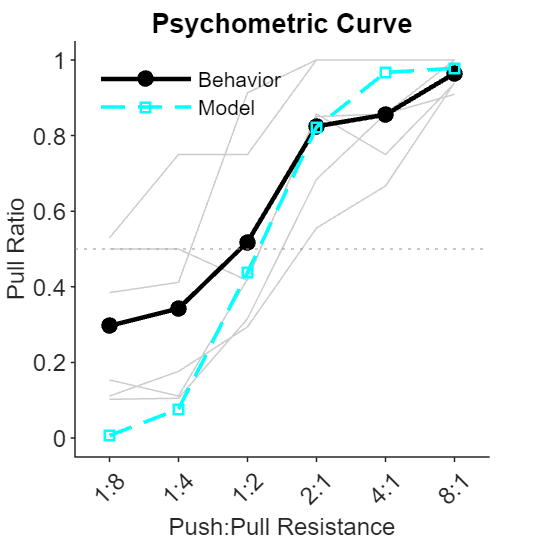

%% 7. プロット実行 (全動物ループ終了後)
x_labels = {'1:8', '1:4', '1:2', '2:1', '4:1', '8:1'};
x_values = 1:6;

% 全体平均の算出
mean_pull_ratio_beh = nanmean(animal_pull_ratio_beh, 2);
mean_pull_ratio_mod = nanmean(animal_pull_ratio_mod, 2);

% --- フィギュア作成 ---
figure('Units', 'inches', 'Position', [1, 1, 2.5, 2.5], 'Color', 'w');
hold on;

% 1. 個体データ (背景・薄いグレー)
plot(x_values, animal_pull_ratio_beh, 'Color', [0.8 0.8 0.8], 'LineWidth', 0.5, 'HandleVisibility', 'off');

% 2. Behavior 平均 (太い黒)
plot(x_values, mean_pull_ratio_beh, '-o', 'Color', 'k', 'LineWidth', 1.5, ...
    'MarkerSize', 4, 'MarkerFaceColor', 'k', 'DisplayName', 'Behavior');

% 3. Model 平均 (太いシアン)
plot(x_values, mean_pull_ratio_mod, '--s', 'Color', 'c', 'LineWidth', 1.2, ...
    'MarkerSize', 4, 'MarkerFaceColor', 'none', 'DisplayName', 'Model');

% 軸のスタイル調整
set(gca, 'Box', 'off', 'TickDir', 'out', 'FontSize', 8, 'XTick', x_values, ...
    'XTickLabel', x_labels, 'XTickLabelRotation', 45);
ylabel('Pull Ratio', 'FontSize', 8);
xlabel('Push:Pull Resistance', 'FontSize', 8);
title('Psychometric Curve', 'FontSize', 9);
ylim([-0.05 1.05]); xlim([0.5 6.5]);

% 50%ライン
yline(0.5, ':', 'Color', [0.6 0.6 0.6], 'HandleVisibility', 'off');

legend('Location', 'northwest', 'FontSize', 7, 'Box', 'off');

% 保存
saveas(gcf, fullfile(output_dir, 'Psychometric_Curve_Final.svg'));

% %% カテゴリ別の縦並びプロット (12パネル構成)
% 
% % カテゴリ分類ロジック (前回のロジックを継承)
% idx_SS = []; idx_SF = []; idx_RS = []; idx_RF = [];
% F_threshold = 16; 
% 
% for i_trial = 1:totalTrial
%     force = force_cell{i_trial};
%     reward = data_raw{j_animal, i_trial}(end, 5);
%     correct_side = (pullResistance(i_trial) < pushResistance(i_trial));
% 
%     if reward == 1
%         choice_side = correct_side;
%     else
%         choice_side = 1 - correct_side;
%     end
% 
%     first_move_idx = find(abs(force) > F_threshold, 1);
%     if isempty(first_move_idx), continue; end
% 
%     initial_side = (force(first_move_idx) > 0);
%     is_straight = (initial_side == choice_side);
% 
%     if is_straight && (reward == 1)
%         idx_SS = [idx_SS, i_trial];
%     elseif is_straight && (reward == 0)
%         idx_SF = [idx_SF, i_trial];
%     elseif ~is_straight && (reward == 1)
%         idx_RS = [idx_RS, i_trial];
%     elseif ~is_straight && (reward == 0)
%         idx_RF = [idx_RF, i_trial];
%     end
% end
% 
% % プロット設定
% categories = {idx_SS, idx_SF, idx_RS, idx_RF};
% cat_names = {'Straight Success', 'Straight Fail', 'Reverse Success', 'Reverse Fail'};
% var_names = {'Position (mm)', 'Force (mN)', 'Posterior (Pull)'};
% 
% % 縦に長い図を作成 (4カテゴリ × 3変数)
% figure('Name', 'Stacked Pattern Analysis', 'Position', [100, 50, 1200, 900]);
% tlo = tiledlayout(3, 4, 'TileSpacing', 'compact', 'Padding', 'compact');
% 
% for c = 1:4 % 各列がカテゴリ
%     target_trials = categories{c};
% 
%     if isempty(target_trials)
%         % データがない場合は空のタイトルを表示
%         for v = 1:3
%             nexttile((v-1)*4 + c);
%             title([cat_names{c} ' (No Data)']);
%         end
%         continue;
%     end
% 
%     % 代表トライアルのデータ取得
%     t_idx = target_trials(1);
%     time = time_cell{t_idx} - time_cell{t_idx}(1);
%     data_to_plot = {position_cell{t_idx}, force_cell{t_idx}, pull_posterior_cell{t_idx}};
%     colors = {'k', [0.5 0.5 0.5], 'c'};
% 
%     % 3つの変数を縦に並べる
%     for v = 1:3
%         ax = nexttile((v-1)*4 + c);
%         plot(time, data_to_plot{v}, 'Color', colors{v}, 'LineWidth', 1.5);
% 
%         % 初動のタイミングをマーク (全パネルに表示)
%         fm_idx = find(abs(force_cell{t_idx}) > F_threshold, 1);
%         hold on;
%         plot(time(fm_idx), data_to_plot{v}(fm_idx), 'ro', 'MarkerFaceColor', 'r');
% 
%         % 装飾
%         if v == 1
%             title(cat_names{c}, 'FontSize', 12);
%         end
%         if c == 1
%             ylabel(var_names{v}, 'FontWeight', 'bold');
%         end
%         if v == 3
%             xlabel('Time (ms)');
%             ylim([-0.1 1.1]);
%             yline(0.5, '--', 'Color', [0.7 0.7 0.7]);
%         end
%         grid on;
%     end
% end
% 
% sgtitle(['Stacked Behavioral Analysis: ' Animal{j_animal} ' - Trial Type Comparison'], 'FontSize', 14);
% 
% % 画像の保存
% filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_stacked_patterns.png'];
% saveas(gcf, filename);

%% 1. 全個体データの集約と補完処理 (最新ロジック対応版)
dt = 100; 
F_thresh = 16;
pos_thresh_push = 687;
pos_thresh_pull = 657;
reward_window_ms = 1000;

% アライメント窓の設定
windows = {0:dt:2000, -1000:dt:1000, -2000:dt:0};
align_names = {'Trial Start', 'Force Threshold', 'Trial End'};

% プール [Side(2) x Success(2) x Straight(2) x Align(3) x Var(3)]
grand_data_pool = cell(2, 2, 2, 3, 3);

for j_animal = 1:length(Animal)
    fprintf('Processing Animal (%d/%d): %s...\n', j_animal, length(Animal), Animal{j_animal});
    
    % 個体データの読み込み (Preprocess済みの .mat を想定)
    data_folder = [data_parent_dir filesep Date{j_animal} '_' Animal{j_animal} '_' Key{j_animal}];
    mat_filename = [data_folder filesep Animal{j_animal} '_behavior_' Date{j_animal} '_' Key{j_animal} '.mat'];
    load(mat_filename); % bayesian_neural_time, pushCorrect 等
    
    % 列定義 (bayesian_neural_time の構造)
    % 1:Time, 2:Trial, 3:PullRes, 4:PushRes, 5:Vel, 6:Force, 7:PullLik..., 9:PullPost
    % ※ 報酬(Reward)は Preprocess 時の 8列目にあると想定
    % data = bayesian_neural_time;
    t_axis = bayesian_neural_time(:,1);
    trial_ids = bayesian_neural_time(:,2);
    f_axis = behavior_neural_time(:,7);
    p_axis = behavior_neural_time(:,6); % もしPosが別変数なら調整
    post_axis = bayesian_neural_time(:,9); % Pull Posterior
    rew_axis = behavior_neural_time(:,8); % Preprocessで作成した報酬列

    u_trials = unique(trial_ids(trial_ids > 0));
    
    for i = 1:length(u_trials)
        t_id = u_trials(i);
        t_idx = find(trial_ids == t_id);
        
        % --- 1. 判定ロジック（前回と同様） ---
        pos_trial = p_axis(t_idx);
        first_push = find(pos_trial >= pos_thresh_push, 1);
        first_pull = find(pos_trial <= pos_thresh_pull, 1);
        if isempty(first_push) && isempty(first_pull), continue; end
        
        if isempty(first_pull) || (~isempty(first_push) && first_push < first_pull)
            choice_side = 0; 
        else
            choice_side = 1; 
        end

        % 成功判定（終了後1秒以内）
        end_time = t_axis(t_idx(end));
        post_range = find(t_axis > end_time & t_axis <= (end_time + reward_window_ms));
        is_success = ~isempty(post_range) && any(rew_axis(post_range) == 1);

        % 初動とThreshold点の特定
        f_trial = f_axis(t_idx);
        idx_all_thresh = find(abs(f_trial) > F_thresh, 1);
        if isempty(idx_all_thresh), continue; end
        initial_side = (f_trial(idx_all_thresh) > 0);
        is_straight = (initial_side == choice_side);

        if choice_side == 1
            t_thresh_idx_local = find(f_trial > F_thresh, 1);
        else
            t_thresh_idx_local = find(f_trial < -F_thresh, 1);
        end
        if isempty(t_thresh_idx_local), continue; end
        t_thresh_idx = t_idx(1) + t_thresh_idx_local - 1;

        % --- 2. トライアル開始前のPosterior初期値（Prior）の決定 ---
        % 推論ループと同じ論理を適用
        if strcmp(session_type, 'StimProb') && exist('pushCorrect','var')
            % pushCorrect は 0.8 等の Push=Light である確率
            % Pull Posterior は P(Pull=Light) なので、1 - pushCorrect を使用
            init_prior_post = 1 - pushCorrect(t_id); 
        else
            init_prior_post = 0.5;
        end

        % --- 3. データの抽出・補完・格納 ---
        c_side = (behavior_neural_time(t_idx(1), 11) < behavior_neural_time(t_idx(1), 10)); % PullRes < PushRes
        raw_vals = [pos_trial, f_trial, post_axis(t_idx)];
        t_raw = t_axis(t_idx) - t_axis(t_idx(1));
        
        for a = 1:3 
            if a == 1,     t_ref = t_raw(1);
            elseif a == 2, t_ref = t_axis(t_thresh_idx) - t_axis(t_idx(1));
            else,          t_ref = t_raw(end);
            end
            
            target_win = windows{a};
            for v = 1:3
                y_interp = interp1(t_raw - t_ref, raw_vals(:, v), target_win, 'linear');
                
                % --- 端点補完ロジックの修正 ---
                % 開始前 (target_win < min_range) の処理
                pre_trial_mask = target_win < min(t_raw - t_ref);
                if v == 3 % Posterior の場合
                    y_interp(pre_trial_mask) = init_prior_post; % 指定された Prior で埋める
                else
                    y_interp(pre_trial_mask) = raw_vals(1, v);   % 位置・力はトライアル開始値
                end
                
                % 終了後 (target_win > max_range) の処理
                post_trial_mask = target_win > max(t_raw - t_ref);
                y_interp(post_trial_mask) = raw_vals(end, v); % 全変数で最終値を維持
                
                % プールに蓄積
                grand_data_pool{c_side+1, is_success+1, is_straight+1, a, v} = ...
                    [grand_data_pool{c_side+1, is_success+1, is_straight+1, a, v}; y_interp];
            end
        end
    end
end

Processing Animal (1/6): C6J501...
Processing Animal (2/6): C6J501...
Processing Animal (3/6): C6J501...
Processing Animal (4/6): C6J501...
Processing Animal (5/6): C6J501...
Processing Animal (6/6): C6J501...


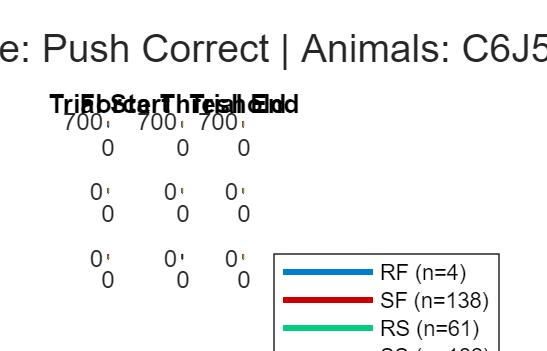

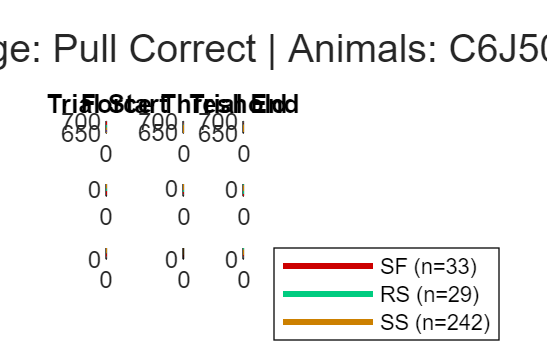


%% 2. プロット作成と保存 (STDシャドウ付き)
var_names = {'Position', 'Force', 'Posterior'};
y_labels = {'au', 'mN', 'P(Pull)'};
colors_mat = [0 0.5 0.8; 0.8 0 0; 0 0.8 0.5; 0.8 0.5 0]; % カスタム色

for side = 0:1
    fig = figure('Name', sprintf('Global_Side_%d', side), 'Position', [50, 50, 1400, 900]);
    tlo = tiledlayout(3, 3, 'TileSpacing', 'compact');
    side_label = containers.Map([1 0], {'Pull Correct', 'Push Correct'});

    for v = 1:3 % 行: 変数
        for a = 1:3 % 列: アライメント
            nexttile; hold on;
            cat_idx = 1;
            cat_list = {'RF', 'SF', 'RS', 'SS'}; % 表示用ラベル

            for succ = 0:1
                for str = 0:1
                    combined_data = grand_data_pool{side+1, succ+1, str+1, a, v};
                    if isempty(combined_data), cat_idx = cat_idx + 1; continue; end

                    mu = nanmean(combined_data, 1);
                    sem = nanstd(combined_data, 0, 1); % ./ sqrt(sum(~isnan(combined_data), 1));
                    t_vec = windows{a};
                    cur_col = colors_mat(cat_idx,:);

                    % STDの塗りつぶし
                    fill([t_vec, fliplr(t_vec)], [mu+sem, fliplr(mu-sem)], cur_col, ...
                        'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
                    
                    % 平均線
                    plot(t_vec, mu, 'Color', cur_col, 'LineWidth', 2, ...
                        'DisplayName', sprintf('%s (n=%d)', cat_list{cat_idx}, size(combined_data,1)));

                    cat_idx = cat_idx + 1;
                end
            end

            if v == 1, title(align_names{a}); end
            if a == 1, ylabel(y_labels{v}); end
            if v == 3, xlabel('Time (ms)'); end
            if v == 3 && a == 2, xline(0, 'k--'); end
            if v == 1 && a == 1 % Positionの閾値を表示
                yline(pos_thresh_push, 'r:'); yline(pos_thresh_pull, 'b:');
            end
            grid on;
        end
    end
    sgtitle(sprintf('Group Average: %s | Animals: %s', side_label(side), strjoin(unique(Animal), ', ')));
    legend('show', 'Location', 'northeastoutside');

    save_name = sprintf('Group_%s_Aligned_%s.png', strjoin(unique(Animal), '_'), strrep(side_label(side),' ','_'));
    saveas(fig, fullfile(output_dir, save_name));
end

% %% 1. 全個体データの集約と補完処理
% dt = 100; % 16msステップ
% F_thresh = 16;
% 
% % アライメント窓の設定
% windows = {0:dt:2000, -1000:dt:1000, -2000:dt:0};
% align_names = {'Trial Start', 'Force Threshold', 'Trial End'};
% 
% % プール [Side(2) x Success(2) x Straight(2) x Align(3) x Var(3)]
% grand_data_pool = cell(2, 2, 2, 3, 3);
% 
% for j_animal = 1:length(Animal)
%     fprintf('Processing Animal (%d/%d): %s...\n', j_animal, length(Animal), Animal{j_animal});
% 
%     % --- 個体データの読み込み ---
%     data_folders(j_animal) = {[data_parent_dir filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
%     load([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_behavior_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat']);
% 
%     for i_trial = 1:totalTrial
%         % 基本属性の取得 (i_trial を使用)
%         reward = behavior_sequence{i_trial}(end, 5); % behavior_sequence を使用
%         c_side = (pullResistance(i_trial) < pushResistance(i_trial)); % 1:Pull, 0:Push
%         force = force_cell{i_trial};
% 
%         if reward == 1, choice_side = c_side; else, choice_side = 1 - c_side; end
% 
%         % アライメントポイントの特定
%         idx_all_thresh = find(abs(force) > F_thresh);
%         if isempty(idx_all_thresh), continue; end
% 
%         first_move_side = (force(idx_all_thresh(1)) > 0);
%         is_straight = (first_move_side == choice_side);
% 
%         if is_straight
%             t_align_idx = idx_all_thresh(1);
%         else
%             if choice_side == 1, t_align_idx = find(force > F_thresh, 1);
%             else, t_align_idx = find(force < -F_thresh, 1);
%             end
%         end
%         if isempty(t_align_idx), continue; end
% 
%         % --- データの補完処理 (tid ではなく i_trial を使用) ---
%         t_raw = time_cell{i_trial} - time_cell{i_trial}(1);
%         % 変数をまとめ直す
%         raw_vals = [position_cell{i_trial}, force_cell{i_trial}, pull_posterior_cell{i_trial}];
% 
%         for a = 1:3 % 3 Alignments
%             if a == 1,     t_ref = t_raw(1);
%             elseif a == 2, t_ref = t_raw(t_align_idx);
%             else,          t_ref = t_raw(end);
%             end
% 
%             for v = 1:3 % 3 Variables
%                 % 線形補完を実行
%                 y_interp = interp1(t_raw - t_ref, raw_vals(:, v), windows{a}, 'linear', NaN);
% 
%                 % grand_data_pool に蓄積
%                 grand_data_pool{c_side+1, reward+1, is_straight+1, a, v} = ...
%                     [grand_data_pool{c_side+1, reward+1, is_straight+1, a, v}; y_interp];
%             end
%         end
%     end
% end
% 
% %% 2. プロット作成と保存
% var_names = {'Position', 'Force', 'Posterior'};
% y_labels = {'mm', 'mN', 'P(Pull)'};
% colors_mat = lines(4);
% 
% for side = 0:1
%     fig = figure('Name', sprintf('Global_Side_%d', side), 'Position', [50, 50, 1400, 900]);
%     tlo = tiledlayout(3, 3, 'TileSpacing', 'compact');
% 
%     side_map = containers.Map([1 0], {'Pull Correct', 'Push Correct'});
%     curr_side_name = side_map(side);
% 
%     for v = 1:3 % 行: 変数
%         for a = 1:3 % 列: アライメント
%             nexttile; hold on;
%             cat_idx = 1;
% 
%             for succ = 0:1
%                 for str = 0:1
%                     % プールからデータを取得
%                     combined_data = grand_data_pool{side+1, succ+1, str+1, a, v};
%                     if isempty(combined_data), cat_idx = cat_idx + 1; continue; end
% 
%                     % 全個体・全トライアルの平均とSEM
%                     mu = nanmean(combined_data, 1);
%                     sem = nanstd(combined_data, 0, 1) ./ sqrt(sum(~isnan(combined_data), 1));
% 
%                     % 平均線のプロット
%                     plot(windows{a}, mu, 'Color', colors_mat(cat_idx,:), 'LineWidth', 2, ...
%                         'DisplayName', sprintf('Succ:%d, Straight:%d (n=%d)', succ, str, size(combined_data,1)));
% 
%                     % (オプション) SEMのシャドウを表示したい場合はここに追加
%                     % fill([windows{a}, fliplr(windows{a})], [mu+sem, fliplr(mu-sem)], ...
%                     %      colors_mat(cat_idx,:), 'FaceAlpha', 0.2, 'EdgeColor', 'none', 'HandleVisibility', 'off');
% 
%                     cat_idx = cat_idx + 1;
%                 end
%             end
% 
%             if v == 1, title(align_names{a}); end
%             if a == 1, ylabel(y_labels{v}); end
%             if v == 3, xlabel('Time (ms)'); end
%             if v == 3 && a == 2, xline(0, 'r--'); end
%             grid on;
%         end
%     end
% 
%     % 保存処理
%     all_animals_str = strjoin(unique(Animal), '_');
%     sgtitle(sprintf('Group Average (Correct Side: %s) | Animals: %s', curr_side_name, all_animals_str));
%     legend('show', 'Location', 'northeastoutside');
% 
%     save_name = sprintf('Group_%s_Aligned_%s.png', all_animals_str, strrep(curr_side_name, ' ', '_'));
%     saveas(fig, fullfile(output_dir, save_name));
%     fprintf('Saved group plot: %s\n', save_name);
% end

% % Calculate resistance posterior and predictin error based on observation
% % 前のバージョン：速度と力の比率ベースの観測の計算
% % position_temp = data{j_animal,i_trial}(:,3)
% 
% data_raw = cell(length(Animal),totalTrial);
% for j_animal = 1:length(Animal)
%     data_folders(j_animal) = {[data_parent_dir filesep strjoin(Date(j_animal)) '_' strjoin(Animal(j_animal)) '_' strjoin(Key(j_animal))]};
%     load([strjoin(data_folders(j_animal)) filesep strjoin(Animal(j_animal)) '_behavior_' strjoin(Date(j_animal)) '_' strjoin(Key(j_animal)) '.mat']);
%     data_raw(j_animal,:) = behavior_sequence; %behavior_sequence_fps; 
% 
%     obs_pull_cell = cell(1,200);
%     obs_push_cell = cell(1,200);
%     pull_correct_cell = cell(1,200);
%     force_cell = cell(1,200);
%     time_cell = cell(1,200);
%     position_cell = cell(1,200);    
%     all_forces = [];
%     all_velocities = [];
% 
%     for i_trial = 1:size(data_raw, 2)
%         position_temp = data_raw{j_animal,i_trial}(:,3);
%         force_temp = data_raw{j_animal,i_trial}(:,4);
%         time_temp = data_raw{j_animal,i_trial}(:,6);
%         % speed_temp = data_raw{j_animal,i_trial}(:,7);
%         % pushResistance_temp = pushResistance(i_trial);
%         % pullResistance_temp = pullResistance(i_trial);
%         % resistance_temp = data_raw{j_animal,i_trial}(:,2);
%         % res_cell{i_trial} = resistance_temp/8 -1;
%         position_velocity = (position_temp(2:end)-position_temp(1:end-1)) ./ (time_temp(2:end)-time_temp(1:end-1));
%         all_forces = [all_forces; force_temp(1:end-1)];
%         all_velocities = [all_velocities; position_velocity];
%         obs_temp = [position_velocity ./ (force_temp(1:end-1) + 1e-8)];
%         pull_idx = find(force_temp(1:end-1) > 0);
%         push_idx = find(force_temp(1:end-1) < 0);
%         obs_pull = obs_temp .* (force_temp(1:end-1) > 0); %obs_temp(pull_idx);
%         obs_push = obs_temp .* (force_temp(1:end-1) < 0); %obs_temp(push_idx);
%         % obs2 = [0; (position_temp(2:end)-position_temp(1:end-1)) ./ (force_temp(1:end-1) + 1e-8)];
%         % obs2 = speed_temp ./ (force_temp + 1e-8);
%         % obs2 = [0; speed_temp(2:end) ./ (force_temp(1:end-1) + 1e-8)];
%         obs_pull_cell{i_trial} = [0; obs_pull];
%         obs_push_cell{i_trial} = [0; obs_push];
%         force_cell{i_trial} = force_temp;
%         pull_correct_cell{i_trial} = ones([size(obs_temp, 1) + 1, size(obs_temp, 2)]) * (pushResistance(i_trial) > pullResistance(i_trial));
%         time_cell{i_trial} = time_temp;
%         position_cell{i_trial} = position_temp;
%         % obs2_omit0 = [speed_temp(2:end) ./ (force_temp(1:end-1) + 1e-8)];
%         % obs2_omit0_cell{i_trial} = obs2_omit0;
%     end
% 
%     figure;
%     scatter(all_forces, all_velocities, 10, 'filled', 'MarkerFaceAlpha', 0.2); % 点を小さく、半透明にして見やすくする
% 
%     % グラフの装飾
%     title('Position Velocity vs. Force (All Trials)');
%     xlabel('Force');
%     ylabel('Position Velocity');
%     grid on;
% 
%     % resistance_table = readtable([strjoin(data_folders(j_animal)) filesep 'resistance.csv']);
%     % resistance = resistance_table.('resistance'); % state1: 8 (light) or 16-64 (heavy)
%     pull_correct_idx = find(pushResistance > pullResistance);
%     push_correct_idx = find(pushResistance < pullResistance);       
%     push_easy_idx    = find(pushResistance == 16);
%     push_mid_idx     = find(pushResistance == 32);
%     push_diff_idx    = find(pushResistance == 64);
%     pull_easy_idx    = find(pullResistance == 16);
%     pull_mid_idx     = find(pullResistance == 32);
%     pull_diff_idx    = find(pullResistance == 64);    
%     % heavy_idx = find(resistance ~= 8);
%     % light_idx = find(resistance == 8);
% 
%     obs_correct   = [obs_push_cell(push_correct_idx), obs_pull_cell(pull_correct_idx)];
%     obs_incorrect = [obs_push_cell(pull_correct_idx), obs_pull_cell(push_correct_idx)];
%     obs_easy      = [obs_push_cell(push_easy_idx), obs_pull_cell(pull_easy_idx)];
%     obs_mid       = [obs_push_cell(push_mid_idx), obs_pull_cell(pull_mid_idx)];
%     obs_diff      = [obs_push_cell(push_diff_idx), obs_pull_cell(pull_diff_idx)];
% 
%     % 
%     % transpose obs cell to array
%     obs_correct_array = cell2mat(obs_correct(:));
%     obs_incorrect_array = cell2mat(obs_incorrect(:));
%     obs_easy_array = cell2mat(obs_easy(:));
%     obs_mid_array = cell2mat(obs_mid(:));
%     obs_diff_array = cell2mat(obs_diff(:));
% 
%     % 外れ値を取り除く (絶対値が1以下の要素を残す)
%     obs_correct_array = obs_correct_array((obs_correct_array <= -0.0001) & (obs_correct_array > -0.02)); %-2));
%     obs_incorrect_array = obs_incorrect_array((obs_incorrect_array <= -0.0001) & (obs_incorrect_array > -0.02));
%     obs_easy_array = obs_easy_array((obs_easy_array <= -0.0001) & (obs_easy_array > -0.02));
%     obs_mid_array = obs_mid_array((obs_mid_array <= -0.0001) & (obs_mid_array > -0.02));
%     obs_diff_array = obs_diff_array((obs_diff_array <= -0.0001) & (obs_diff_array > -0.02));    
%     % 1. 単位換算係数を先に計算
%     conversion_factor = -(300 * 30 * 1000* pi) / (1024 * 180);
%     % obs2の分布とフィッティング比較
%     all_data = {obs_correct_array,obs_incorrect_array,obs_easy_array,obs_mid_array,obs_diff_array};
%     all_labels = {'8 mN','16~64 mN','16 mN','32 mN','64 mN'};
%     % 2. cellfunを使用して各セル内の配列に変換係数を適用
%     all_data_converted = cellfun(@(x) x * conversion_factor, all_data, 'UniformOutput', false);    
%     fit_and_compare(all_data_converted,all_labels, 'Observation');
%     % fit_and_compare(obs_light_array, obs_heavy_array, 'light', 'heavy', 'Distribution and Fit: observation (speed/force)');
%     filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_observation_dist.png'];
%     saveas(gcf,filename);
% 
%     [obs_mean0, v0] = normfit(obs_correct_array);
%     [obs_mean1, v1] = normfit(obs_incorrect_array);    
%     [obs_mean2, v2] = normfit(obs_easy_array);
%     [obs_mean3, v3] = normfit(obs_mid_array);
%     [obs_mean4, v4] = normfit(obs_diff_array);    
% 
%     obs_mean = [obs_mean0; obs_mean1; obs_mean2; obs_mean3; obs_mean4]; %[obs_mean0; obs_mean1] % heavy, light
%     v = [v0; v1; v2; v3; v4]; %[v0; v1]
%     pull_prior = 0.5;push_prior = 0.5;
%     pull_likelihood_cell = cell(1,200); %zeros(length(obs2_valid), 1);
%     push_likelihood_cell = cell(1,200); %zeros(length(obs2_valid), 1);
%     pull_posterior_cell = cell(1,200); %zeros(length(obs2_valid), 1);
%     push_posterior_cell = cell(1,200); %zeros(length(obs2_valid), 1);    
%     pull_neg_log_likelihood_cell = cell(1,200); 
%     push_neg_log_likelihood_cell = cell(1,200);     
% 
%     for i_trial = 1:length(obs_pull_cell)
%         obs_pull_valid = obs_pull_cell{i_trial};
%         obs_push_valid = obs_push_cell{i_trial};
%         force_valid = force_cell{i_trial};
%         pull_likelihood_list = zeros(length(obs_pull_valid), 1);
%         push_likelihood_list = zeros(length(obs_push_valid), 1);
%         pull_posterior_list = zeros(length(obs_pull_valid), 1);
%         push_posterior_list = zeros(length(obs_push_valid), 1);
%         for n = 1:length(obs_pull_cell{i_trial})
%             if obs_pull_valid(n) ~= 0 %force_valid(n-1) >= 0 %
%                 pull_likelihood_light = max(normpdf(obs_pull_valid(n), obs_mean(1), v(1)), 1e-8); 
%                 pull_likelihood_heavy = max(normpdf(obs_pull_valid(n), obs_mean(2), v(2)), 1e-8);  
%                 pull_likelihood = pull_likelihood_light / (pull_likelihood_heavy+pull_likelihood_light);
%                 pull_likelihood = max(min(pull_likelihood, 0.9) ,0.1); % prevent outside obs
%                 pull_likelihood_list(n) = pull_likelihood;             
%                 % product
%                 pull_prilik = pull_prior * pull_likelihood;
%                 push_prilik = push_prior * (1 - pull_likelihood);
%                 % posterior by normalization
%                 marginal = pull_prilik + push_prilik;
%                 push_likelihood_list(n) = 1 - pull_likelihood; %NaN
%                 pull_posterior = pull_prilik / marginal;
%                 push_posterior = push_prilik / marginal;
%             elseif obs_push_valid(n) ~= 0 % force_valid(n-1) < 0 %
%                 push_likelihood_light = max(normpdf(obs_push_valid(n), obs_mean(1), v(1)), 1e-8); 
%                 push_likelihood_heavy = max(normpdf(obs_push_valid(n), obs_mean(2), v(2)), 1e-8); 
%                 push_likelihood = push_likelihood_light / (push_likelihood_heavy+push_likelihood_light);
%                 push_likelihood = max(min(push_likelihood, 0.9) ,0.1); % prevent outside obs
%                 push_likelihood_list(n) = push_likelihood;  
%                 push_prilik = push_prior * push_likelihood;  
%                 pull_prilik = pull_prior * (1 - push_likelihood);
%                 marginal = pull_prilik + push_prilik;
%                 pull_likelihood_list(n) = 1 - push_likelihood; %NaN
%                 pull_posterior = pull_prilik / marginal;
%                 push_posterior = push_prilik / marginal;
%             else
%                 push_likelihood_list(n) = 0.5;
%                 pull_likelihood_list(n) = 0.5;
%                 pull_posterior = pull_prior;
%                 push_posterior = push_prior; 
%             end
%             pull_posterior_list(n) = pull_posterior;
%             push_posterior_list(n) = push_posterior;
%             % posterior as a new prior
%             pull_prior = min(max(pull_posterior, 0.01), 0.99);
%             push_prior = min(max(push_posterior, 0.01), 0.99);
%         end
%         pull_neg_log_likelihood_list = zeros(length(pull_posterior_list), 1);
%         push_neg_log_likelihood_list = zeros(length(push_posterior_list), 1);
%         for n = 1:length(pull_likelihood_list)
%             pull_neg_log_likelihood_list(n) = -log(pull_likelihood_list(n)); 
%             push_neg_log_likelihood_list(n) = -log(push_likelihood_list(n)); 
%             % if ~isnan(pull_likelihood_list(n))
%             %     pull_neg_log_likelihood_list(n) = -log(pull_likelihood_list(n)); 
%             % elseif ~isnan(push_likelihood_list(n))
%             %     push_neg_log_likelihood_list(n) = -log(push_likelihood_list(n)); 
%             % end
%         end
%         pull_likelihood_cell{i_trial} = pull_likelihood_list;
%         push_likelihood_cell{i_trial} = push_likelihood_list;
%         pull_posterior_cell{i_trial} = pull_posterior_list;
%         push_posterior_cell{i_trial} = push_posterior_list;
%         pull_neg_log_likelihood_cell{i_trial} = pull_neg_log_likelihood_list;
%         push_neg_log_likelihood_cell{i_trial} = push_neg_log_likelihood_list;
%     end
% 
%     % % plot timecourse of all trials
%     % figure;
%     % plot((resistance_temp-8)/8, 'b'); % resistance
%     % hold on;
%     % plot(obs2_valid, 'g'); % observation
%     % plot(posterior_list, 'm'); % posterior by normalization
%     % plot(prediction_error_list, 'y'); % prediction error
%     % xlabel('Timestep');
%     % ylabel('P(s=H)');
%     % ylim([-0.1, 1.1]);
%     % legend({'resistance', 'observation', 'posterior','prediction error'});
%     % hold off;
%     pull_neg_log_likelihood_mat = cell2mat(pull_neg_log_likelihood_cell(:)); %/20;
%     push_neg_log_likelihood_mat = cell2mat(push_neg_log_likelihood_cell(:));
%     pull_correct_mat = cell2mat(pull_correct_cell(:));
%     pull_posterior_mat = cell2mat(pull_posterior_cell(:));
%     pull_obs_mat = cell2mat(obs_pull_cell(:));
%     push_obs_mat = cell2mat(obs_push_cell(:));
%     pull_likelihood_mat = cell2mat(pull_likelihood_cell(:));
%     push_likelihood_mat = cell2mat(push_likelihood_cell(:));
%     force_mat = cell2mat(force_cell(:));
%     position_mat = cell2mat(position_cell(:));
%     time_mat = cell2mat(time_cell(:));    
% 
%     % plot timecourse of all trials
%     figure;
%     hold on;
%     % plot(pull_neg_log_likelihood_mat, '-b', 'DisplayName', 'Pull Neg Log Likelihood');
%     % plot(push_neg_log_likelihood_mat, '--b', 'DisplayName', 'Push Neg Log Likelihood');
%     % 
%     % plot(pull_obs_mat, '-g', 'DisplayName', 'Pull Observation');
%     % plot(push_obs_mat, '--g', 'DisplayName', 'Push Observation');
%     % 
%     % plot(pull_likelihood_mat, '-r', 'DisplayName', 'Pull Likelihood');
%     % plot(push_likelihood_mat, '--r', 'DisplayName', 'Push Likelihood');
% 
%     plot(pull_posterior_mat, '-c', 'DisplayName', 'Pull Posterior');
%     plot(pull_correct_mat, '-m', 'DisplayName', 'Pull Correct');
%     % xlabel('Timestep');
% 
%     xlim([2000, 4000]);
%     ylabel('P(s=Pull)');
%     ylim([-0.1, 1.1]);
%     legend('show', 'Location', 'northeastoutside'); %{'resistance', 'posterior','prediction error'});
%     hold off;
%     filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_Bayesian_sequence.png'];
%     saveas(gcf,filename);
% 
%     % --- 修正後のプロットコード ---
%     figure;
%     hold on;
% 
%     % X軸の範囲を、元のインデックス[2000, 4000]に対応する時間(ms)に設定
%     % time_matが空でないこと、インデックスが範囲内であることを確認
%     if length(time_mat) > 2500
%         xlim_start = time_mat(2000);
%         xlim_end = time_mat(2500);
%     else
%         xlim_start = time_mat(1);
%         xlim_end = time_mat(end);
%     end
% 
%     % --- 左側のY軸 (Posterior) ---
%     yyaxis left    
%     plot(time_mat, pull_posterior_mat, '-c', 'LineWidth', 1.5, 'DisplayName', 'Pull Posterior');
%     plot(time_mat, pull_correct_mat, '-m', 'LineWidth', 1.5, 'DisplayName', 'Pull Light');
% 
%     ylabel('P(s=Pull)');
%     ylim([-0.1, 1.1]);
%     ax = gca;
%     ax.YColor = 'k'; % 左軸の色を黒に
% 
%     % --- 右側のY軸 (Force & Position) ---
%     yyaxis right
%     position_mat_z = zscore(-position_mat);
%     force_mat_z = zscore(force_mat);    
%     plot(time_mat, position_mat_z, '-', 'Color', [0 0 0], 'LineWidth', 1.5, 'DisplayName', 'Position');
%     plot(time_mat, force_mat_z, '--', 'Color', [0.6 0.6 0.6], 'LineWidth', 1.5, 'DisplayName', 'Force');
% 
%     ylabel('Force / Position (a.u.)');
%     ax = gca;
%     ax.YColor = 'k'; % 右軸の色を黒に
% 
%     % --- 共通の装飾 ---
%     xlabel('Time (ms)');
%     xlim([xlim_start, xlim_end]);
%     legend('show', 'Location', 'northeastoutside');
%     title('Bayesian Observer, Force, and Position over Time');
%     grid on;
%     hold off;
% 
%     filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_Bayesian_sequence_with_kinematics.png'];
%     saveas(gcf,filename);
% 
%     pull_correct_array = zeros(200,1);
%     map_array = zeros(200,1);
%     for i_trial = 1:200 %length(res_cell)
%         bayesian_sequence{i_trial} = [pull_correct_cell{i_trial} obs_pull_cell{i_trial} obs_push_cell{i_trial} pull_likelihood_cell{i_trial} push_likelihood_cell{i_trial} pull_posterior_cell{i_trial} push_posterior_cell{i_trial} pull_neg_log_likelihood_cell{i_trial} push_neg_log_likelihood_cell{i_trial}];
%         pull_correct_array(i_trial) = pull_correct_cell{i_trial}(end);
%         map_array(i_trial) = (pull_posterior_cell{i_trial}(end) >= 0.5);
%         % bayesian_sequence{i_trial} = [res_cell{i_trial} obs2_cell{i_trial} likelihood_cell{i_trial} likelihood_cell1{i_trial} posterior_cell{i_trial} prediction_error_cell{i_trial}];
%     % bayesian_sequence{i_trial} = [res_mat obs_mat likelihood_heavy_mat likelihood_light_mat posterior_mat prediction_error_mat];
%     end
%     save([data_folders{j_animal} filesep Animal{j_animal} '_behavior_' Date{j_animal} '_' Key{j_animal} '.mat'], 'bayesian_sequence', '-append');
%     % bayesian_neural_time_clip = [res_mat obs_mat likelihood_heavy_mat likelihood_light_mat posterior_mat prediction_error_mat];
%     % save([data_folders{j_animal} filesep Animal{j_animal} '_behavior_' Date{j_animal} '_' Key{j_animal} '.mat'], 'bayesian_neural_time_clip', '-append');
% 
%     % 2. 正解率を算出
%     % map_arrayとpull_correct_matが一致する要素の数を数え、全要素数で割る
%     accuracy = sum(map_array == pull_correct_array) / 200;
%     pull_bias = sum(map_array) / 200
% 
%     % 3. 結果を表示
%     fprintf('モデルの正解率: %.2f%%\n', accuracy * 100); 
% 
%     % --- 全トライアルの尤度を連結してヒストグラムを描画 ---
% 
%     % 1. セル配列を1つの長いベクトルに変換
%     all_pull_likelihoods = cell2mat(pull_likelihood_cell(:));
%     all_push_likelihoods = cell2mat(push_likelihood_cell(:));
%     valid_pull_likelihoods = all_pull_likelihoods(~isnan(all_pull_likelihoods));
%     valid_push_likelihoods = all_push_likelihoods(~isnan(all_push_likelihoods));
% 
%     % 3. ヒストグラムを描画
%     figure;
%     hold on;
%     histogram(valid_pull_likelihoods, 'BinEdges', 0:0.02:1, 'Normalization', 'probability');
%     histogram(valid_push_likelihoods, 'BinEdges', 0:0.02:1, 'Normalization', 'probability');    
% 
%     % 4. グラフの装飾
% 
%     % バイアスの有無を視覚的に判断しやすくするため、中央(0.5)に赤線を引く
%     xline(0.5, '--r', 'LineWidth', 2, 'DisplayName', 'Center (0.5)');
% 
%     title('Distribution of All Calculated Likelihoods');
%     xlabel('Likelihood');
%     ylabel('Probability');
%     legend('show');
%     grid on;    
% end

% --- シミュレーションパラメータ (分析全体で共通) ---
env_type = "LeverPushPullSwitch";
tmax = 200;
gamma = 0.9; % 割引率

% =================================================================
% --- 動物ごとのバッチ処理ループ ---
% =================================================================
for j_animal = 1:length(Animal)
    
    fprintf('\n\n==================================================\n');
    fprintf('--- Processing Animal: %s ---\n', Animal{j_animal});
    fprintf('==================================================\n');

    % --- データのロード ---
    % .matファイルには behavior_sequence, pushResistance, pullResistance, pushReward が
    % 保存されていることを想定しています。
    data_filename = sprintf('%s_behavior_%s_%s.mat', Animal{j_animal}, Date{j_animal}, Key{j_animal});
    load(fullfile(data_folders{j_animal}, data_filename));
    
    % --- 時系列データから価値を推定 (モデルフリー：モンテカルロ法) ---
    time_cai = (1:200)'; % 縦ベクトルに修正
    reward_cai_raw = cellfun(@(x) x(end, 5), behavior_sequence);
    state_cai = (pullResistance < pushResistance) * 1 + (pullResistance > pushResistance) * 2;
    action_cai = (transpose(reward_cai_raw) == 1) .* state_cai + (transpose(reward_cai_raw) == 0) .* (3 - state_cai);
    reward_cai = (pullResistance < pushResistance) .* transpose(reward_cai_raw) .* (4-pushReward) + (pullResistance > pushResistance) .* transpose(reward_cai_raw) .* pushReward;
    
    Trsa = [time_cai, reward_cai, state_cai, action_cai];
    
    ns = 2; na = 2; % 状態数と行動数
    [V_est_mc, Q_est_mc, A_est_mc] = CAI_estimate_value_from_history(Trsa, ns, na, gamma);

    fprintf('\n--- Model-Free Estimation (Monte Carlo) for %s ---\n', Animal{j_animal});
    fprintf('Estimated State Values (V_est):\n'); disp(V_est_mc');
    fprintf('Estimated Action Values (Q_est):\n'); disp(Q_est_mc);
    fprintf('Estimated Advantages (A_est):\n'); disp(A_est_mc);

    % --- モデルベースでの価値推定（オンライン逐次更新） ---
    fprintf('\n--- Model-Based Estimation (Online) for %s ---\n', Animal{j_animal});
    agent_for_estimation = CAI(ns, na, tmax, env_type);
    agent_for_estimation.beta = 10;
    reward_schedule_raw = pushReward;
    reward_schedule_raw(reward_schedule_raw == 2) = 0;
    reward_schedule_raw(reward_schedule_raw == 3) = 2;
    agent_for_estimation.reward_schedule = reward_schedule_raw;

    [V_hist, Q_hist, A_hist, final_agent] = CAI_estimate_value_model_based(Trsa, agent_for_estimation);
    
    fprintf('Final estimated values (model-based) for %s:\n', Animal{j_animal});
    fprintf('V_est:\n'); disp(final_agent.V');
    fprintf('Q_est:\n'); disp(final_agent.Q);
    fprintf('A_est:\n'); disp(final_agent.Advantage);
    
    
    % =================================================================
    % --- プロットと保存 ---
    % =================================================================
    
    % --- Plot Episode History ---
    fig1 = figure('Position', [100, 100, 600, 300], 'Visible', 'off');
    plot(Trsa(:,1), Trsa(:,2), 'LineWidth', 1.5); hold on;
    plot(Trsa(:,1), Trsa(:,3), 'LineWidth', 1.5);
    plot(Trsa(:,1), Trsa(:,4), 'LineWidth', 1.5);
    xlabel("Time (a.u.)"); ylabel("Value");
    legend(["Reward", "State", "Action"], 'Location', 'eastoutside');
    title(sprintf('Episode History for %s (%s)', Animal{j_animal}, env_type));
    grid on;
    saveas(fig1, fullfile(output_dir, sprintf('%s_episode_history.png', Animal{j_animal})));

    % % --- Plot Agent's Internal Dynamics (Model-Based) ---
    % agent = final_agent; % モデルベース推定後のエージェントを使用
    % action_value = cell2mat(agent.logged_action_value');
    % next_state_pred = cell2mat(agent.logged_next_state_prediction');
    % reward_next = cell2mat(agent.logged_reward_next');
    % state_value = cell2mat(agent.logged_state_value');
    % advantage = cell2mat(agent.logged_advantage');
    % action_hist = cell2mat(agent.logged_action');
    % t_array = 0:tmax;
    % 
    % fig2 = figure('Position', [100, 100, 400, 800], 'Visible', 'off');
    % tiledlayout(6, 1, 'TileSpacing', 'compact');
    % % Panel 1: Action Value
    % nexttile; plot(t_array, action_value(:,1), 'r', 'DisplayName', 'Q(a=1)'); hold on; plot(t_array, action_value(:,2), 'g', 'DisplayName', 'Q(a=2)'); title('Action Value'); legend('Location', 'eastoutside'); set(gca, 'XTickLabel', []);
    % % Panel 2: Prediction
    % nexttile; plot(t_array, next_state_pred(:,1), 'b', 'DisplayName', "s'(a=1)"); hold on; plot(t_array, next_state_pred(:,2), 'c', 'DisplayName', "s'(a=2)"); title('Prediction'); legend('Location', 'eastoutside'); set(gca, 'XTickLabel', []);
    % % Panel 3: Reward
    % nexttile; plot(t_array, reward_next(:,1), 'm', 'DisplayName', 'r(a=1)'); hold on; plot(t_array, reward_next(:,2), 'color', [0.5 0 0.5], 'DisplayName', 'r(a=2)'); title('Reward'); legend('Location', 'eastoutside'); set(gca, 'XTickLabel', []);
    % % Panel 4: State Value
    % nexttile; plot(t_array, state_value, 'color', [0.9 0.6 0]); title('State Value'); set(gca, 'XTickLabel', []);
    % % Panel 5: Advantage
    % nexttile; plot(t_array, advantage(:,1), 'color', [0.5 0 0.5], 'DisplayName', 'A(a=1)'); hold on; plot(t_array, advantage(:,2), 'c', 'DisplayName', 'A(a=2)'); title('Advantage'); legend('Location', 'eastoutside'); set(gca, 'XTickLabel', []);
    % % Panel 6: Action
    % nexttile; plot(t_array, action_hist, 'k'); title('Action'); xlabel('Time (a.u.)');
    % saveas(fig2, fullfile(output_dir, sprintf('%s_internal_dynamics.png', Animal{j_animal})));

    % --- モデルベース価値推定の結果をプロット ---
    time_axis = 0:tmax-1;
    % V(s) のプロット
    fig3 = figure('Name', 'MB V(s)', 'Position', [200, 500, 700, 300], 'Visible', 'off');
    plot(time_axis, V_hist, 'LineWidth', 2); title(sprintf('Model-Based V(s) Over Time for %s', Animal{j_animal})); xlabel('Time (a.u.)'); ylabel('State Value'); legend(arrayfun(@(i) sprintf('V(State %d)', i), 1:ns, 'UniformOutput', false), 'Location', 'best'); grid on;
    saveas(fig3, fullfile(output_dir, sprintf('%s_model_based_V.png', Animal{j_animal})));

    % Q(s,a) のプロット
    fig4 = figure('Name', 'MB Q(s,a)', 'Position', [200, 100, 700, 300], 'Visible', 'off');
    hold on; for s = 1:ns, for a = 1:na, plot(time_axis, squeeze(Q_hist(:, s, a)), 'LineWidth', 1.5, 'DisplayName', sprintf('Q(s=%d, a=%d)', s, a)); end, end, hold off;
    title(sprintf('Model-Based Q(s,a) Over Time for %s', Animal{j_animal})); xlabel('Time (a.u.)'); ylabel('Action Value'); legend('Location', 'best'); grid on;
    saveas(fig4, fullfile(output_dir, sprintf('%s_model_based_Q.png', Animal{j_animal})));

    % A(s,a) のプロット
    fig5 = figure('Name', 'MB A(s,a)', 'Position', [950, 100, 700, 300], 'Visible', 'off');
    hold on; for s = 1:ns, for a = 1:na, plot(time_axis, squeeze(A_hist(:, s, a)), 'LineWidth', 1.5, 'DisplayName', sprintf('A(s=%d, a=%d)', s, a)); end, end, hold off;
    title(sprintf('Model-Based A(s,a) Over Time for %s', Animal{j_animal})); xlabel('Time (a.u.)'); ylabel('Advantage'); legend('Location', 'best'); grid on;
    saveas(fig5, fullfile(output_dir, sprintf('%s_model_based_A.png', Animal{j_animal})));

    % --- 結果を構造体にまとめて保存 ---
    results = struct();
    results.animal_id = Animal{j_animal};
    results.Trsa = Trsa;
    % Model-Free results
    results.V_est_mc = V_est_mc;
    results.Q_est_mc = Q_est_mc;
    results.A_est_mc = A_est_mc;
    % Model-Based results
    results.V_hist_mb = V_hist;
    results.Q_hist_mb = Q_hist;
    results.A_hist_mb = A_hist;
    results.final_agent = final_agent;

    save_filename = fullfile(data_folders{j_animal}, sprintf('%s_cai_results.mat', Animal{j_animal}));
    save(save_filename, 'results');
    fprintf('Saved results for %s to %s\n', Animal{j_animal}, save_filename);
    
    % --- このループで開いた図をすべて閉じる ---
    close all;
    
end

--- Processing Animal: C6J501 ---


Undefined variable 'data_folders'.


fprintf('\n\n--- All animals processed. ---\n');

% % --- Simulation Parameters ---
% % env_type = "LeverPushPull";
% env_type = "LeverPushPullSwitch";
% 
% tmax = 200;
% 
% % --- Setup Environment and Agent ---
% if strcmp(env_type, "LeverPushPull")
%     ns = 2; na = 2;
%     env = LeverPushPull();
% elseif strcmp(env_type, "LeverPushPullSwitch")
%     ns = 2; na = 2;
%     env = LeverPushPullSwitch(tmax);
% else
%     error("Unknown environment type");
% end
% 
% agent = CAI(ns, na, tmax, env_type);
% agent.beta = 10;
% 
% % --- Run a Single Episode ---
% Trsa = zeros(tmax + 1, 4); % Time, Reward, State, Action
% state = env.start();
% action = agent.start(state);
% 
% Trsa(1,:) = [0, 0, state, action];
% 
% for t = 1:tmax
%     [reward, next_state] = env.step(action);
%     [agent, action] = agent.step(reward, next_state);
%     Trsa(t+1, :) = [t, reward, next_state, action];
% end
% 
% % --- 時系列データから価値を推定 (モデルフリー：モンテカルロ法) ---
% time_cai = 1:200
% reward_cai_raw = cellfun(@(x) x(end, 5), behavior_sequence);
% state_cai = (pullResistance < pushResistance) * 1 + (pullResistance > pushResistance) * 2;
% action_cai = (reward_cai_raw == 1) .* state_cai + (reward_cai_raw == 0) .* (3 - state_cai);
% reward_cai = (pullResistance < pushResistance) * reward_cai_raw * (4-pushReward) + (pullResistance > pushResistance) * reward_cai_raw * pushReward;
% Trsa = [time_cai reward_cai state_cai action_cai];
% gamma = 0.9; % 割引率
% [V_est_mc, Q_est_mc, A_est_mc] = CAI_estimate_value_from_history(Trsa, ns, na, gamma);
% 
% fprintf('\n--- Model-Free Estimation from History (Monte Carlo) ---\n');
% fprintf('Estimated State Values (V_est):\n');
% disp(V_est_mc');
% 
% fprintf('Estimated Action Values (Q_est):\n');
% disp(Q_est_mc);
% 
% fprintf('Estimated Advantages (A_est):\n');
% disp(A_est_mc);
% 
% 
% % --- Plot Episode History ---
% figure('Position', [100, 100, 600, 300]);
% plot(Trsa(:,1), Trsa(:,2), 'LineWidth', 1.5); hold on;
% plot(Trsa(:,1), Trsa(:,3), 'LineWidth', 1.5);
% plot(Trsa(:,1), Trsa(:,4), 'LineWidth', 1.5);
% xlabel("Time (a.u.)");
% ylabel("Value");
% legend(["Reward", "State", "Action"], 'Location', 'eastoutside');
% title(['Episode History for ', env_type]);
% grid on;
% 
% % --- Plot Agent's Internal Dynamics ---
% action_value = cell2mat(agent.logged_action_value');
% next_state_pred = cell2mat(agent.logged_next_state_prediction');
% reward_next = cell2mat(agent.logged_reward_next');
% state_value = cell2mat(agent.logged_state_value');
% advantage = cell2mat(agent.logged_advantage');
% action_hist = cell2mat(agent.logged_action');
% t_array = 0:tmax;
% 
% figure('Position', [100, 100, 400, 800]);
% tiledlayout(6, 1, 'TileSpacing', 'compact');
% 
% % Panel 1: Action Value
% nexttile;
% plot(t_array, action_value(:,1), 'r', 'LineWidth', 1, 'DisplayName', 'Q(a=1)'); hold on;
% plot(t_array, action_value(:,2), 'g', 'LineWidth', 1, 'DisplayName', 'Q(a=2)');
% title('Action Value'); legend('Location', 'eastoutside');
% set(gca, 'XTickLabel', []);
% 
% % Panel 2: Prediction
% nexttile;
% plot(t_array, next_state_pred(:,1), 'b', 'LineWidth', 1, 'DisplayName', "s'(a=1)"); hold on;
% plot(t_array, next_state_pred(:,2), 'c', 'LineWidth', 1, 'DisplayName', "s'(a=2)");
% title('Prediction'); legend('Location', 'eastoutside');
% set(gca, 'XTickLabel', []);
% 
% % Panel 3: Reward
% nexttile;
% plot(t_array, reward_next(:,1), 'm', 'LineWidth', 1, 'DisplayName', 'r(a=1)'); hold on;
% plot(t_array, reward_next(:,2), 'color', [0.5 0 0.5], 'LineWidth', 1, 'DisplayName', 'r(a=2)');
% title('Reward'); legend('Location', 'eastoutside');
% set(gca, 'XTickLabel', []);
% 
% % Panel 4: State Value
% nexttile;
% plot(t_array, state_value, 'color', [0.9 0.6 0], 'LineWidth', 1);
% title('State Value');
% set(gca, 'XTickLabel', []);
% 
% % Panel 5: Advantage
% nexttile;
% plot(t_array, advantage(:,1), 'color', [0.5 0 0.5], 'LineWidth', 1, 'DisplayName', 'A(a=1)'); hold on;
% plot(t_array, advantage(:,2), 'c', 'LineWidth', 1, 'DisplayName', 'A(a=2)');
% title('Advantage'); legend('Location', 'eastoutside');
% set(gca, 'XTickLabel', []);
% 
% % Panel 6: Action
% nexttile;
% plot(t_array, action_hist, 'k', 'LineWidth', 1);
% title('Action');
% xlabel('Time (a.u.)');
% 
% % --- モデルベースでの価値推定（オンライン逐次更新） ---
% fprintf('\nEstimating values step-by-step using the model-based agent...\n');
% agent_for_estimation = CAI(ns, na, tmax, env_type);
% agent_for_estimation.beta = 10;
% reward_schedule_raw = pushReward;
% reward_schedule_raw(reward_schedule_raw == 2) = 0;
% reward_schedule_raw(reward_schedule_raw == 3) = 2;
% agent_for_estimation.reward_schedule = reward_schedule_raw;
% 
% % 変更した関数を呼び出し
% [V_hist, Q_hist, A_hist, final_agent] = CAI_estimate_value_model_based(Trsa, agent_for_estimation);
% 
% fprintf('Final estimated state values (model-based):\n'); disp(final_agent.V');
% fprintf('Final estimated action values (model-based):\n'); disp(final_agent.Q);
% fprintf('Final estimated advantages (model-based):\n'); disp(final_agent.Advantage);
% 
% % --- モデルベース価値推定の結果をプロット ---
% time_axis = 0:tmax;
% 
% % 状態価値 V(s) のプロット
% figure('Name', 'Model-Based Estimation: V(s)', 'Position', [200, 500, 700, 300]);
% plot(time_axis, V_hist, 'LineWidth', 2);
% title('Model-Based State Value Estimation V(s) Over Time');
% xlabel('Time (a.u.)'); ylabel('State Value');
% legend(arrayfun(@(i) sprintf('V(State %d)', i), 1:ns, 'UniformOutput', false), 'Location', 'best');
% grid on;
% 
% % 行動価値 Q(s,a) のプロット
% figure('Name', 'Model-Based Estimation: Q(s,a)', 'Position', [200, 100, 700, 300]);
% hold on;
% for s = 1:ns
%     for a = 1:na
%         % squeezeで (T+1 x 1 x 1) -> (T+1 x 1) に変換
%         plot(time_axis, squeeze(Q_hist(:, s, a)), 'LineWidth', 1.5, ...
%             'DisplayName', sprintf('Q(s=%d, a=%d)', s, a));
%     end
% end
% hold off;
% title('Model-Based Action Value Estimation Q(s,a) Over Time');
% xlabel('Time (a.u.)'); ylabel('Action Value');
% legend('Location', 'best');
% grid on;
% 
% % アドバンテージ A(s,a) のプロット
% figure('Name', 'Model-Based Estimation: A(s,a)', 'Position', [950, 100, 700, 300]);
% hold on;
% for s = 1:ns
%     for a = 1:na
%         plot(time_axis, squeeze(A_hist(:, s, a)), 'LineWidth', 1.5, ...
%             'DisplayName', sprintf('A(s=%d, a=%d)', s, a));
%     end
% end
% hold off;
% title('Model-Based Advantage Estimation A(s,a) Over Time');
% xlabel('Time (a.u.)'); ylabel('Advantage');
% legend('Location', 'best');
% grid on;

% =================================================================
% --- 動物ごとのバッチ処理ループ ---
% =================================================================
for j_animal = 1:length(Animal)
    
    fprintf('\n==================================================\n');
    fprintf('--- Processing Animal: %s ---\n', Animal{j_animal});
    
    % --- データのロード ---
    % .matファイルには pushCorrect, pullResistance, pushResistance が
    % 保存されていることを想定しています。session_type
    data_filename = sprintf('%s_behavior_%s_%s.mat', Animal{j_animal}, Date{j_animal}, Key{j_animal});
    load_path = fullfile(data_folders{j_animal}, data_filename);
    
    % ファイルが存在するか確認
    if ~exist(load_path, 'file')
        fprintf('Warning: Data file not found for %s. Skipping.\n -> %s\n', Animal{j_animal}, load_path);
        continue; % 見つからない場合はこの動物をスキップ
    end
    
    load(load_path, 'pushCorrect', 'pullResistance', 'pushResistance');
    
    % --- 動的ベイジアン推論の実行 ---
    xt = pullResistance < pushResistance;
    run_lengths = diff([0, transpose(find(diff(pushCorrect) ~= 0)), numel(pushCorrect)]);
    blockLength = run_lengths(2:end-1);
    max_resistance = max(pushResistance, pullResistance);
    trialLevels = NaN(size(max_resistance));
    trialLevels(max_resistance == 64) = 0;
    trialLevels(max_resistance == 32) = 1;
    trialLevels(max_resistance == 16) = 2;

    fprintf('Running dynamic Bayesian inference for %s...\n', Animal{j_animal});
    if strcmp(session_type, 'StimProb')
        [pst, post, map_estimate, nll] = dynamic_bayesian_inference(5, 3, xt, 'BlockLength', blockLength, 'TrialLevels', trialLevels);
    else
        [pst, post, map_estimate, nll] = dynamic_bayesian_inference(6, 3, xt, 'TrialLevels', trialLevels);
    end
    
    %% プロット
    figure;
    subplot(3,1,1);
    plot(xt,'-o'); hold on;
    plot(map_estimate-1,'--x');
    legend('True state','MAP estimate');
    title('True vs MAP estimated states');
    
    subplot(3,1,2);
    imagesc(post'); colorbar;
    ylabel('State'); xlabel('Trial');
    title('Posterior distribution');
    
    subplot(3,1,3);
    plot(nll);
    title('Negative Log Likelihood');
    xlabel('Trial');
    ylabel('NLL');

    filename = [output_dir Date{j_animal} '_' Animal{j_animal} '_DBI_session_sequence.png'];
    saveas(gcf,filename);

    % --- 結果を構造体にまとめて保存 ---
    results = struct();
    results.animal_id = Animal{j_animal};
    results.pst = pst;
    results.post = post;
    results.map_estimate = map_estimate;
    results.nll = nll;
    % 推論に使った入力データも一緒に保存しておくと便利です
    results.inputs.xt = xt;
    results.inputs.blockLength = blockLength;
    results.inputs.trialLevels = trialLevels;

    save_filename = fullfile(data_folders{j_animal}, sprintf('%s_inference_results.mat', Animal{j_animal}));
    save(save_filename, 'results');
    fprintf('Saved results for %s to %s\n', Animal{j_animal}, save_filename);
    
    % 次のループのために変数をクリア
    clear pushCorrect pullResistance pushResistance results;
end

fprintf('\n--- All animals processed. ---\n');

% xt = pullResistance < pushResistance;
% run_lengths = diff([0, find(diff(pushCorrect) ~= 0), numel(pushCorrect)]);
% blockLength = run_lengths(2:end-1);
% max_resistance = max(pushResistance, pullResistance);
% trialLevels = NaN(size(max_resistance)); 
% trialLevels(max_resistance == 64) = 0;
% trialLevels(max_resistance == 32) = 1;
% trialLevels(max_resistance == 16) = 2;
% [pst, post, map_estimate, nll] = dynamic_bayesian_inference(5, 3, xt, 'BlockLength', blockLength, 'TrialLevels', trialLevels);

function [pst, post, map_estimate, nll] = dynamic_bayesian_inference(env, level, xt, varargin)
    % Dynamic Bayesian Inference (MATLAB version)
    % env=5: Value block, env=6: No block
    % level: 0=Easy, 1=Middle, 2=Hard, 3=Mixed
    rng(42); % 乱数初期化
    T = 200; % trial数

    % 既定値
    blockLength = [];   % デフォルトはランダム生成
    trialLevels = [];   % デフォルトはランダム生成
    
    % オプション解析
    for i = 1:2:length(varargin)
        switch varargin{i}
            case 'BlockLength'
                block_len = varargin{i+1};
            case 'TrialLevels'
                level_trials = varargin{i+1};
            otherwise
                error('Unknown option %s', varargin{i});
        end
    end
  
    block_cur = 2*ones(T,1); % ブロック番号
    if env == 5
        cum_block_len = 20;
        % block_len = zeros(4,1);
        for i=1:4
            % block_len(i) = randi([35,45],1);
            block_start = cum_block_len+1;
            block_end   = cum_block_len + block_len(i);
            block_cur(block_start:block_end) = mod(i-1,2);
            % % 状態生成
            % xt(block_start:block_end) = randsample([0,1], block_len(i), true, prob_block(i,:));
            cum_block_len = block_end;
        end
    end

    %% 環境設定
    if env == 5
        ns = 2; % 状態数
        ps = 0.2;
    elseif env == 6
        ns = 2;
        ps = 0.5;
    else
        error('env=5 or 6 only supported in this script.');
    end
    no = 2; % 観測数
    
    %% 観測モデル
    if level == 0
        po = 0.9;
    elseif level == 1
        po = 0.75;
    elseif level == 2
        po = 0.6;
    else
        po = 0.5; % mixture later
    end
    Pobs = zeros(no, ns);
    Pobs(1,1) = po; Pobs(2,2) = po;
    Pobs(2,1) = 1-po; Pobs(1,2) = 1-po;
    
    %% 真の状態系列生成

    xt = zeros(T,1);
    yt = zeros(T,1);
    if isempty(level_trials)
        level_trials = zeros(T,1);
    end
    
    prob_block = zeros(4,ns);
    if env == 5
        prob_block(1,:) = [0.8 0.2];
        prob_block(2,:) = [0.2 0.8];
        prob_block(3,:) = [0.8 0.2];
        prob_block(4,:) = [0.2 0.8];
    elseif env == 6
        prob_block(:,:) = 0.5; % 無バイアス
    end
   
    
    for t=1:T
        if level==3
            % 混合難易度
            values = [0,1,2];
            probs  = [0.5,0.25,0.25];
            if isempty(level_trials)
                level_trial = randsample(values,1,true,probs);
                level_trials(t) = level_trial;
            else
                level_trial = level_trials(t);
            end
            if level_trial==0
                po = 0.9;
            elseif level_trial==1
                po = 0.75;
            else
                po = 0.6;
            end
            Pobs(1,1) = po; Pobs(2,2) = po;
            Pobs(2,1) = 1-po; Pobs(1,2) = 1-po;
        end
        yt(t) = randsample([1,2],1,true,Pobs(:,xt(t)+1));
    end
    
    %% HMMベイズ推論
    pst = ones(1,ns)/ns; % 初期分布
    post = zeros(T,ns);
    map_estimate = zeros(T,1);
    nll = zeros(T,ns);
    
    for t=1:T
        % 遷移行列設定
        if t<=20 || block_cur(t)==2 || env==6
            Ptr = [0.5 0.5; 0.5 0.5];
        elseif (block_cur(t-1)==xt(t-1)) && env==5
            Ptr = [0.8 0.2; 0.2 0.8];
        else
            Ptr = [0.2 0.8; 0.8 0.2];
        end
        
        % 予測
        pred = pst * Ptr';
        
        % 更新
        obs_idx = yt(t);
        likelihood = Pobs(obs_idx,:); % P(y|x)
        prl = likelihood .* pred;
        pst = prl / sum(prl);
        
        post(t,:) = pst;
        [~,map_estimate(t)] = max(pst);
        
        % 負の対数尤度
        nll(t,:) = -log(max(Pobs(obs_idx,:),1e-12));
    end
    
    %% 一致率の算出
    acc = mean((xt(:)+1)==map_estimate(:))*100;
    fprintf('全体の一致率: %.2f%%\n', acc);
    
    if level==3
        for l=0:2
            idx = (level_trials==l);
            acc_level = mean((xt(idx)+1)==map_estimate(idx))*100;
            fprintf('Level %d の一致率: %.2f%%\n', l, acc_level);
        end
    end
end

function fit_and_compare(dataArrays, labels, titleStr)
    % dataArrays: データ配列を格納したセル配列
    % labels:     各データのラベルを格納したセル配列
    % titleStr:   グラフ全体のタイトル

    % --- 初期設定 ---
    num_datasets = numel(dataArrays); % データセットの数を取得
    colors = lines(num_datasets);     % データセットの数だけ異なる色を自動生成
    
    figure; % 新しい図ウィンドウを作成
    hold on; % 複数のグラフを重ね描きする設定

    % 全データを通したx軸の範囲を計算
    all_data_combined = vertcat(dataArrays{:});
    x_range = linspace(0.0,2.0,200); %linspace(-0.02,0.0,200); %(min(all_data_combined), max(all_data_combined), 200);

    % --- forループで各データセットを処理 ---
    for i = 1:num_datasets
        % i番目のデータ、ラベル、色を取得
        current_data = dataArrays{i};
        current_label = labels{i};
        current_color = colors(i, :);
        
        % データが空の場合はスキップ
        if isempty(current_data)
            continue;
        end

        % ガウス分布のフィッティング
        [mu, sigma] = normfit(current_data);
        
        % 1. 凡例に表示する文字列をsprintfで作成
        %    μ (mu) と σ (sigma) の値を含める
        fit_legend_label = sprintf('%s Fit (μ=%.3f, σ=%.3f)', current_label, mu, sigma);
        
        % ヒストグラムのプロット (DisplayNameは元のラベルのまま)
        h = histogram(current_data, x_range, 'Normalization', 'pdf', 'FaceAlpha', 0.5, 'FaceColor', current_color); %, 'DisplayName', current_label);
        h.HandleVisibility = 'off';
        % フィッティング曲線のプロット
        p = normpdf(x_range, mu, sigma);
        % 2. DisplayNameに先ほど作成した文字列を使用
        plot(x_range, p, '-', 'Color', current_color, 'LineWidth', 2, 'DisplayName', fit_legend_label);
        
    end
    
    % --- グラフの全体設定 ---
    hold off;
    title(titleStr);
    xlabel('Speed/Force (mm/sec/mN)');
    % ylabel('Density');
    legend('show', 'Location', 'best'); % 凡例を自動表示
    grid on; % グリッド線を表示
end

% function fit_and_compare(data1, data2, label1, label2, titleStr)
%     % ガウス分布のフィッティング
%     [mu1, std1] = normfit(data1);
%     [mu2, std2] = normfit(data2);
% 
%     % ヒストグラムのプロット
%     histogram(data1, 30, 'Normalization', 'pdf', 'FaceAlpha', 0.6, 'FaceColor', 'blue');
%     hold on;
%     histogram(data2, 30, 'Normalization', 'pdf', 'FaceAlpha', 0.6, 'FaceColor', 'red');
% 
%     % フィッティング曲線のプロット
%     x = linspace(min([data1; data2]), max([data1; data2]), 100);
%     p1 = normpdf(x, mu1, std1);
%     p2 = normpdf(x, mu2, std2);
%     plot(x, p1, 'b-', 'LineWidth', 2);
%     plot(x, p2, 'r-', 'LineWidth', 2);
% 
%     % グラフの設定
%     title(titleStr);
%     xlabel('Value');
%     ylabel('Density');
%     legend({[label1 ' Fit'], [label2 ' Fit']});
%     hold off;
% end